clear;
close;
load('simulation_results_nominal.mat');

% --- Common Plot Configuration ---
fig_size = [0, 0, 315, 250]; % Figure size in pixels
plotFontSize = 10;           % Font size for labels, legends, titles
axisFontSize = 10;           % Font size for axis ticks
lineWidth = 1.5;             % Line width for plots
fontName = 'Times New Roman'; % Font for all text
outputFormat = '-dpdf';      % Output format: '-dpdf', '-depsc', '-dtiff' (for raster)
outputResolution = '-r300';  % Output resolution for raster formats (e.g., TIFF)
fileExtension = '.pdf';      % File extension matching outputFormat

% Define color scheme: blue, orange, green, red
colorScheme = [25, 115, 178;   % Blue
               255, 127, 14;   % Orange
               44, 160, 44;    % Green
               214, 39, 40]/255; % Red
color1 = colorScheme(1, :);
color2 = colorScheme(2, :);
color3 = colorScheme(3, :);
color4 = colorScheme(4, :);

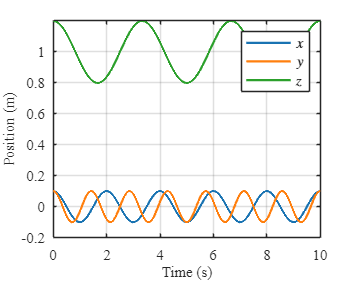

% --- Plot 1: Ground Truth Position ---
fig1 = figure('Name', 'Ground Truth Position');
set(fig1, 'Units', 'pixels', 'Position', fig_size);
hold on;
plot(ground_truth_data.timestamps, ground_truth_data.position(:,1), 'Color', colorScheme(1,:), 'LineWidth', lineWidth);
plot(ground_truth_data.timestamps, ground_truth_data.position(:,2), 'Color', colorScheme(2,:), 'LineWidth', lineWidth);
plot(ground_truth_data.timestamps, ground_truth_data.position(:,3), 'Color', colorScheme(3,:), 'LineWidth', lineWidth);
hold off;
ax = gca; 
ax.FontSize = axisFontSize;
ax.FontName = fontName;
xlabel('Time (s)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Position (m)', 'FontSize', plotFontSize, 'FontName', fontName);
legend({'$x$', '$y$', '$z$'}, 'Location', 'northeast', 'FontSize', plotFontSize, 'FontName', fontName, 'Interpreter', 'latex');
grid on; box on;
xlim([ground_truth_data.timestamps(1), ground_truth_data.timestamps(end)/2]);

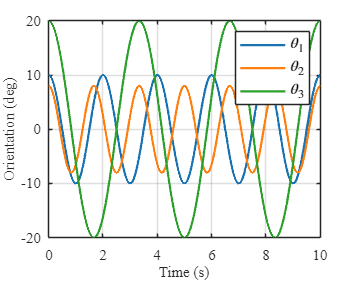

% --- Plot 2: Ground Truth Orientation ---
fig2 = figure('Name', 'Ground Truth Orientation');
set(fig2, 'Units', 'pixels', 'Position', fig_size);
hold on;
plot(ground_truth_data.timestamps, ground_truth_data.orientation(:,1), 'Color', colorScheme(1,:), 'LineWidth', lineWidth);
plot(ground_truth_data.timestamps, ground_truth_data.orientation(:,2), 'Color', colorScheme(2,:), 'LineWidth', lineWidth);
plot(ground_truth_data.timestamps, ground_truth_data.orientation(:,3), 'Color', colorScheme(3,:), 'LineWidth', lineWidth);
hold off;
ax = gca;
ax.FontSize = axisFontSize;
ax.FontName = fontName;
xlabel('Time (s)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Orientation (deg)', 'FontSize', plotFontSize, 'FontName', fontName); % Adjust unit if necessary
legend({'$\theta_1$', '$\theta_2$', '$\theta_3$'}, 'Location', 'northeast', 'FontSize', plotFontSize, 'FontName', fontName,  'Interpreter', 'latex');
grid on;
box on;
xlim([ground_truth_data.timestamps(1), ground_truth_data.timestamps(end) / 2]);

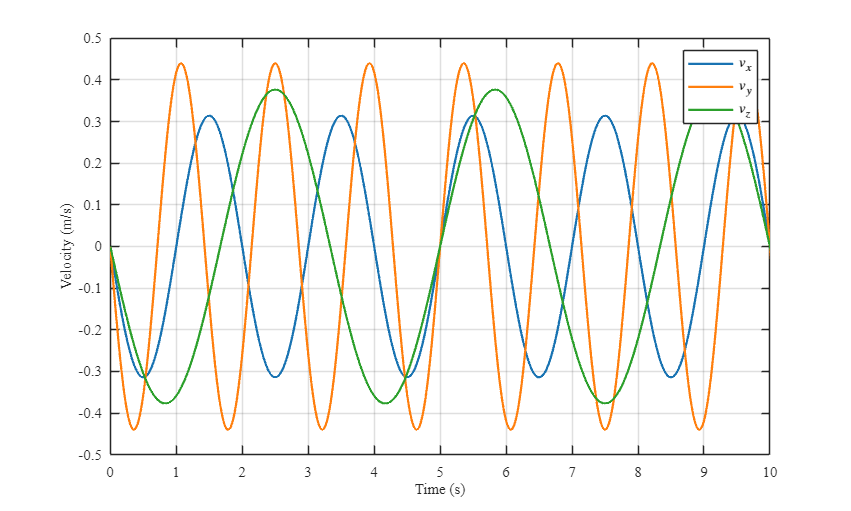

% --- Plot 3: Ground Truth Velocity ---
fig3 = figure('Name', 'Ground Truth Velocity');
set(fig3, 'Units', 'centimeters', 'Position', [0, 0, 20, 12]);
hold on;
plot(ground_truth_data.timestamps, ground_truth_data.velocity(:,1), 'Color', colorScheme(1,:), 'LineWidth', lineWidth);
plot(ground_truth_data.timestamps, ground_truth_data.velocity(:,2), 'Color', colorScheme(2,:), 'LineWidth', lineWidth);
plot(ground_truth_data.timestamps, ground_truth_data.velocity(:,3), 'Color', colorScheme(3,:), 'LineWidth', lineWidth);
hold off;
ax = gca;
ax.FontSize = axisFontSize;
ax.FontName = fontName;
xlabel('Time (s)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Velocity (m/s)', 'FontSize', plotFontSize, 'FontName', fontName);
legend({'$v_x$', '$v_y$', '$v_z$'}, 'Location', 'northeast', 'FontSize', plotFontSize, 'FontName', fontName, 'Interpreter', 'latex');
grid on;
box on;
xlim([ground_truth_data.timestamps(1), ground_truth_data.timestamps(end)/2]);

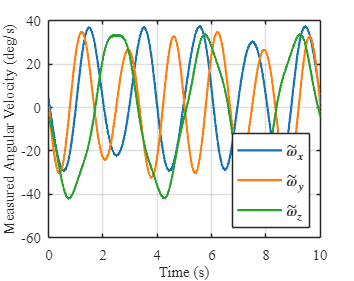

% --- Plot 4: IMU Gyroscope Measurements ---
fig4 = figure('Name', 'IMU Gyroscope');
set(fig4, 'Units', 'pixels', 'Position', fig_size);
hold on;
plot(imu_measure_data.timestamps, imu_measure_data.gyro(:,1), 'Color', colorScheme(1,:), 'LineWidth', lineWidth);
plot(imu_measure_data.timestamps, imu_measure_data.gyro(:,2), 'Color', colorScheme(2,:), 'LineWidth', lineWidth);
plot(imu_measure_data.timestamps, imu_measure_data.gyro(:,3), 'Color', colorScheme(3,:), 'LineWidth', lineWidth);
hold off;
ax = gca;
ax.FontSize = axisFontSize;
ax.FontName = fontName;
xlabel('Time (s)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Measured Angular Velocity (deg/s)', 'FontSize', plotFontSize, 'FontName', fontName); % Adjust unit if necessary
legend({'$\tilde{\omega}_x$', '$\tilde{\omega}_y$', '$\tilde{\omega}_z$'}, 'Location', 'southeast', 'FontSize', plotFontSize, 'FontName', fontName, 'Interpreter', 'latex');
grid on;
box on;
xlim([imu_measure_data.timestamps(1), imu_measure_data.timestamps(end)/2]);

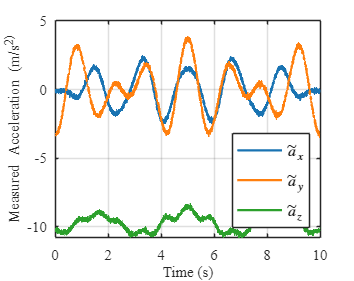

% --- Plot 5: IMU Accelerometer Measurements ---
fig5 = figure('Name', 'IMU Accelerometer');
set(fig5, 'Units', 'pixels', 'Position', fig_size);
hold on;
plot(imu_measure_data.timestamps, imu_measure_data.acce(:,1), 'Color', colorScheme(1,:), 'LineWidth', lineWidth);
plot(imu_measure_data.timestamps, imu_measure_data.acce(:,2), 'Color', colorScheme(2,:), 'LineWidth', lineWidth);
plot(imu_measure_data.timestamps, imu_measure_data.acce(:,3), 'Color', colorScheme(3,:), 'LineWidth', lineWidth);
hold off;
ax = gca;
ax.FontSize = axisFontSize;
ax.FontName = fontName;
xlabel('Time (s)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Measured Acceleration (m/s^2)', 'FontSize', plotFontSize, 'FontName', fontName);
legend({'$\tilde{a}_x$', '$\tilde{a}_y$', '$\tilde{a}_z$'}, 'Location', 'southeast', 'FontSize', plotFontSize, 'FontName', fontName, 'Interpreter', 'latex');
grid on;
box on;
xlim([imu_measure_data.timestamps(1), imu_measure_data.timestamps(end)/2]);

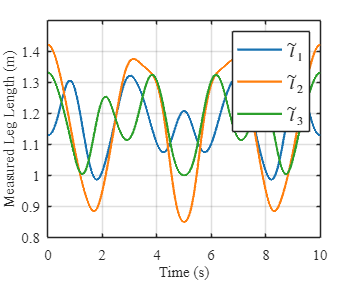

% --- Plot 6: Measured Leg Lengths ---
fig6 = figure('Name', 'Measured Leg Lengths');
set(fig6, 'Units', 'pixels', 'Position', fig_size);
hold on;
plot(leg_measure_data.timestamps, leg_measure_data.L(:,1), 'Color', colorScheme(1,:), 'LineWidth', lineWidth);
plot(leg_measure_data.timestamps, leg_measure_data.L(:,2), 'Color', colorScheme(2,:), 'LineWidth', lineWidth);
plot(leg_measure_data.timestamps, leg_measure_data.L(:,3), 'Color', colorScheme(3,:), 'LineWidth', lineWidth);
% plot(leg_measure_data.timestamps, leg_measure_data.L(:,4), 'Color', colorScheme(3,:), 'LineWidth', lineWidth);
% plot(leg_measure_data.timestamps, leg_measure_data.L(:,5), 'Color', colorScheme(3,:), 'LineWidth', lineWidth);
% % plot(leg_measure_data.timestamps, leg_measure_data.L(:,6), 'Color', colorScheme(3,:), 'LineWidth', lineWidth);
hold off;
ax = gca;
ax.FontSize = axisFontSize;
ax.FontName = fontName;
xlabel('Time (s)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Measured Leg Length (m)', 'FontSize', plotFontSize, 'FontName', fontName);
num_legs = size(leg_measure_data.L, 2);
legend({'$\tilde{l}_1$','$\tilde{l}_2$','$\tilde{l}_3$'}, 'Location', 'northeast', 'FontSize', plotFontSize, 'FontName', fontName, 'Interpreter', 'latex');
grid on;
box on;
xlim([leg_measure_data.timestamps(1), leg_measure_data.timestamps(end)/2]);

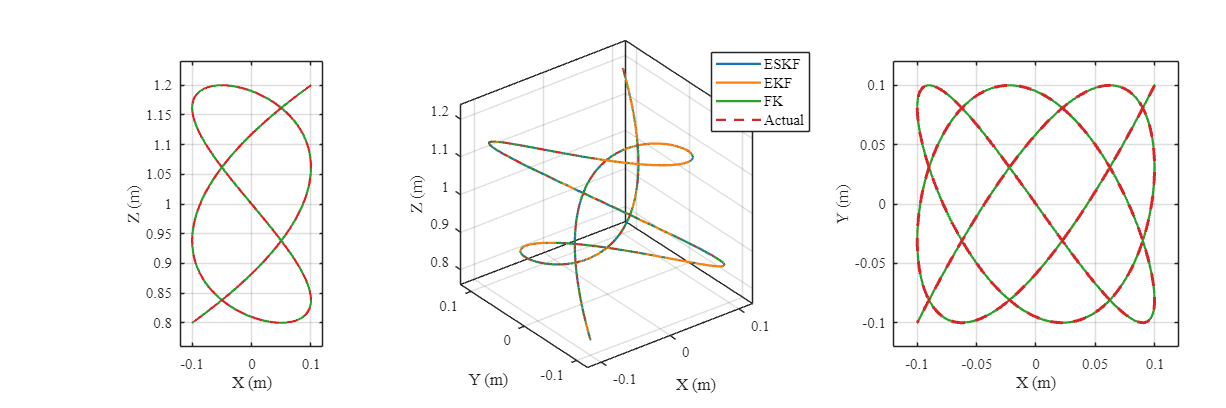

% --- Plot 7: 3D Trajectory Comparison with Projections ---
fig_traj = figure('Name', 'Trajectory Comparison');
set(fig_traj, 'Position', [50, 50, 1500, 500]); % [left, bottom, width, height]
color_gt   = colorScheme(4, :);        
color_eskf = colorScheme(1, :); 
color_ekf  = colorScheme(2, :); 
color_fk   = colorScheme(3, :); 
total_length = length(ground_truth_data.position);
half_length = floor(total_length/4);
pos_gt   = ground_truth_data.position(1:half_length, :);
pos_eskf = est_states_ESKF.position(1:half_length, :);
pos_ekf  = est_states_EKF.position(1:half_length, :);
pos_fk   = est_states_FK.position(1:half_length, :);
subplot_pos = {
    [0.08, 0.15, 0.25, 0.7],    
    [0.32, 0.1, 0.35, 0.8],   
    [0.72, 0.15, 0.25, 0.7]   
};
% --- Center Plot: 3D Trajectory ---
ax_3d = axes('Position', subplot_pos{2}); 
hold on;
plot3(pos_eskf(:,1), pos_eskf(:,2), pos_eskf(:,3), 'Color', color_eskf, 'LineWidth', lineWidth);
plot3(pos_ekf(:,1),  pos_ekf(:,2),  pos_ekf(:,3),  'Color', color_ekf,  'LineWidth', lineWidth);
plot3(pos_fk(:,1),   pos_fk(:,2),   pos_fk(:,3),   'Color', color_fk,   'LineWidth', lineWidth);
plot3(pos_gt(:,1),   pos_gt(:,2),   pos_gt(:,3),   'Color', color_gt,   'LineWidth', lineWidth,  'LineStyle', '--');
hold off;
grid on;
box on;
xlabel('X (m)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Y (m)', 'FontSize', plotFontSize, 'FontName', fontName);
zlabel('Z (m)', 'FontSize', plotFontSize, 'FontName', fontName);
legend({'ESKF', 'EKF', 'FK', 'Actual'}, ...
       'Location', 'northeast', ... 
       'FontSize', plotFontSize, ...
       'FontName', fontName, ...
       'Interpreter', 'none');
view(3); 
ax_3d.FontSize = axisFontSize;
ax_3d.FontName = fontName;
% --- Left Plot: XZ Projection ---
ax_xz = axes('Position', subplot_pos{1});
hold on;
plot(pos_eskf(:,1), pos_eskf(:,3), 'Color', color_eskf, 'LineWidth', lineWidth);
plot(pos_ekf(:,1),  pos_ekf(:,3),  'Color', color_ekf,  'LineWidth', lineWidth);
plot(pos_fk(:,1),   pos_fk(:,3),   'Color', color_fk,   'LineWidth', lineWidth);
plot(pos_gt(:,1),   pos_gt(:,3),   'Color', color_gt,   'LineWidth', lineWidth, 'LineStyle', '--');
hold off;
grid on;
box on;
axis equal; 
xlabel('X (m)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Z (m)', 'FontSize', plotFontSize, 'FontName', fontName);
ax_xz.FontSize = axisFontSize;
ax_xz.FontName = fontName;

% --- Right Plot: XY Projection ---
ax_xy = axes('Position', subplot_pos{3});
hold on;
plot(pos_eskf(:,1), pos_eskf(:,2), 'Color', color_eskf, 'LineWidth', lineWidth);
plot(pos_ekf(:,1),  pos_ekf(:,2),  'Color', color_ekf,  'LineWidth', lineWidth);
plot(pos_fk(:,1),   pos_fk(:,2),   'Color', color_fk,   'LineWidth', lineWidth);
plot(pos_gt(:,1),   pos_gt(:,2),   'Color', color_gt,   'LineWidth', lineWidth + 0.5, 'LineStyle', '--');
hold off;
grid on;
box on;
axis equal; 
xlabel('X (m)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Y (m)', 'FontSize', plotFontSize, 'FontName', fontName);
ax_xy.FontSize = axisFontSize;
ax_xy.FontName = fontName;

all_x = [pos_gt(:,1); pos_eskf(:,1); pos_ekf(:,1); pos_fk(:,1)];
all_y = [pos_gt(:,2); pos_eskf(:,2); pos_ekf(:,2); pos_fk(:,2)];
all_z = [pos_gt(:,3); pos_eskf(:,3); pos_ekf(:,3); pos_fk(:,3)];

x_range = max(all_x) - min(all_x);
y_range = max(all_y) - min(all_y);
z_range = max(all_z) - min(all_z);

x_lims = [min(all_x) - 0.1*x_range, max(all_x) + 0.1*x_range];
y_lims = [min(all_y) - 0.1*y_range, max(all_y) + 0.1*y_range];
z_lims = [min(all_z) - 0.1*z_range, max(all_z) + 0.1*z_range];

set(ax_xz, 'XLim', x_lims);
set(ax_xz, 'YLim', z_lims);  
set(ax_xy, 'XLim', x_lims);
set(ax_xy, 'YLim', y_lims);

max_range = max([x_range, y_range, z_range]);
set(ax_3d, 'DataAspectRatioMode', 'manual');
x_scale = max_range / x_range;
y_scale = max_range / y_range;
z_scale = max_range / z_range;
set(ax_3d, 'DataAspectRatio', [1/x_scale, 1/y_scale, 1/z_scale]);
set(ax_3d, 'XLim', x_lims);
set(ax_3d, 'YLim', y_lims);
set(ax_3d, 'ZLim', z_lims);

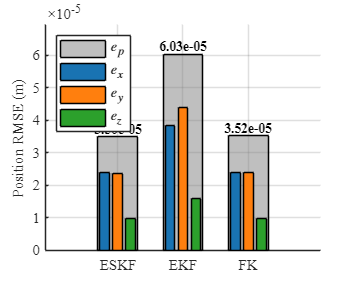

% --- Calculating RMSE values ---
% --- Extract Timestamps ---
t_gt   = ground_truth_data.timestamps;
t_eskf = est_states_ESKF.timestamp;
t_ekf  = est_states_EKF.timestamp;
t_fk   = est_states_FK.timestamp;

% --- Align Data to Ground Truth Timestamps ---
gt_position = ground_truth_data.position;
gt_orientation_eul = ground_truth_data.orientation; % Assumed ZYX Euler [rad]

eskf_pos_interp = interp1(t_eskf, est_states_ESKF.position, t_gt, 'linear', 'extrap');
eskf_eul_interp = interp1(t_eskf, est_states_ESKF.euler, t_gt, 'linear', 'extrap'); % Assumed ZYX Euler [rad]

ekf_pos_interp  = interp1(t_ekf, est_states_EKF.position, t_gt, 'linear', 'extrap');
ekf_eul_interp  = interp1(t_ekf, est_states_EKF.euler, t_gt, 'linear', 'extrap'); % Assumed ZYX Euler [rad]

fk_pos_interp   = interp1(t_fk, est_states_FK.position, t_gt, 'linear', 'extrap');
fk_eul_interp   = interp1(t_fk, est_states_FK.euler, t_gt, 'linear', 'extrap'); % Assumed ZYX Euler [rad]

n_gt = length(t_gt); % Number of points after alignment

% --- Calculate Position Errors ---
eskf_pos_errors = eskf_pos_interp - gt_position;
ekf_pos_errors  = ekf_pos_interp  - gt_position;
fk_pos_errors   = fk_pos_interp   - gt_position;

% --- Calculate Overall Position RMSE (m) ---
eskf_pos_rmse = sqrt(mean(sum(eskf_pos_errors.^2, 2)));
ekf_pos_rmse  = sqrt(mean(sum(ekf_pos_errors.^2, 2)));
fk_pos_rmse   = sqrt(mean(sum(fk_pos_errors.^2, 2)));

% --- Calculate XYZ Position RMSE (m) ---
eskf_pos_rmse_xyz = sqrt(mean(eskf_pos_errors.^2, 1)); % [RMSE_X, RMSE_Y, RMSE_Z]
ekf_pos_rmse_xyz  = sqrt(mean(ekf_pos_errors.^2, 1));
fk_pos_rmse_xyz   = sqrt(mean(fk_pos_errors.^2, 1));

% --- Calculate Overall Orientation RMSE (from Quaternions, deg) ---
gt_quat = zeros(n_gt, 4);
eskf_quat = zeros(n_gt, 4);
ekf_quat = zeros(n_gt, 4);
fk_quat = zeros(n_gt, 4);
for i = 1:n_gt
    gt_quat(i, :)   = eul2quat(deg2rad(gt_orientation_eul(i, :)), 'ZYX');
    eskf_quat(i, :) = eul2quat(deg2rad(eskf_eul_interp(i, :)), 'ZYX');
    ekf_quat(i, :)  = eul2quat(deg2rad(ekf_eul_interp(i, :)), 'ZYX');
    fk_quat(i, :)   = eul2quat(deg2rad(fk_eul_interp(i, :)), 'ZYX');
end
eskf_angle_error = zeros(n_gt, 1); ekf_angle_error = zeros(n_gt, 1); fk_angle_error = zeros(n_gt, 1);
for i = 1:n_gt
    dot_eskf = max(-1, min(1, dot(eskf_quat(i, :), gt_quat(i, :))));
    dot_ekf  = max(-1, min(1, dot(ekf_quat(i, :), gt_quat(i, :))));
    dot_fk   = max(-1, min(1, dot(fk_quat(i, :), gt_quat(i, :))));
    eskf_angle_error(i) = 2 * acos(abs(dot_eskf));
    ekf_angle_error(i)  = 2 * acos(abs(dot_ekf));
    fk_angle_error(i)   = 2 * acos(abs(dot_fk));
end
eskf_ori_rmse_overall = rad2deg(sqrt(mean(eskf_angle_error.^2)));
ekf_ori_rmse_overall  = rad2deg(sqrt(mean(ekf_angle_error.^2)));
fk_ori_rmse_overall   = rad2deg(sqrt(mean(fk_angle_error.^2)));

% --- Calculate Individual Euler Angle RMSE (Roll, Pitch, Yaw, deg) ---
% Assuming ZYX order: gt_orientation_eul(:,1)=Yaw, (:,2)=Pitch, (:,3)=Roll
err_ori_eskf = zeros(n_gt, 3);
err_ori_ekf  = zeros(n_gt, 3);
err_ori_fk   = zeros(n_gt, 3);

if exist('angdiff', 'file') % Use angdiff if available
    for i = 1:3
        err_ori_eskf(:,i) = angdiff(gt_orientation_eul(:,i), eskf_eul_interp(:,i)); % angdiff(target, actual)
        err_ori_ekf(:,i)  = angdiff(gt_orientation_eul(:,i), ekf_eul_interp(:,i));
        err_ori_fk(:,i)   = angdiff(gt_orientation_eul(:,i), fk_eul_interp(:,i));
    end
else
    warning('angdiff function not found. Using simple subtraction for angles, which might be inaccurate due to wrapping.');
    err_ori_eskf = gt_orientation_eul - eskf_eul_interp; % Simple subtraction
    err_ori_ekf  = gt_orientation_eul - ekf_eul_interp;
    err_ori_fk   = gt_orientation_eul - fk_eul_interp;
    % Add manual wrapping here if needed, e.g., err = mod(err + pi, 2*pi) - pi;
end

% Calculate RMSE for each angle (deg)
eskf_ori_rmse_rpy = (sqrt(mean(err_ori_eskf.^2, 1))); % [RMSE_Yaw, RMSE_Pitch, RMSE_Roll]
ekf_ori_rmse_rpy  = (sqrt(mean(err_ori_ekf.^2, 1)));
fk_ori_rmse_rpy   = (sqrt(mean(err_ori_fk.^2, 1)));

% Common variables for plotting
algorithms = {'ESKF', 'EKF', 'FK'};
x_indices = 1:length(algorithms);
bar_width_detail = 0.15;   % Width of the thin bars
group_offset = 0.2;        % Offset from the center
bar_width_overall = 0.6;

% --- Figure 1: Position RMSE ---
% fig_pos_rmse = figure('Name', 'Position RMSE Comparison', 'Position', [100, 100, 550, 450], 'Color', 'w');
fig_pos_rmse = figure('Name', 'Position RMSE Comparison', 'Position', fig_size, 'Color', 'w');

hold on;

pos_rmse_overall = [eskf_pos_rmse, ekf_pos_rmse, fk_pos_rmse];
pos_rmse_xyz = [eskf_pos_rmse_xyz; ekf_pos_rmse_xyz; fk_pos_rmse_xyz]'; % 3xN

% Plot overall RMSE bars
b_pos_overall = bar(x_indices, pos_rmse_overall, bar_width_overall, 'FaceColor', [0.5, 0.5, 0.5], 'FaceAlpha', 0.5, 'EdgeColor','k');

% Plot thin bars for X, Y, Z
b_x = bar(x_indices - group_offset, pos_rmse_xyz(1,:), bar_width_detail, 'FaceColor', color1);
b_y = bar(x_indices,                pos_rmse_xyz(2,:), bar_width_detail, 'FaceColor', color2);
b_z = bar(x_indices + group_offset, pos_rmse_xyz(3,:), bar_width_detail, 'FaceColor', color3);

hold off;

set(gca, 'XTick', x_indices, 'XTickLabel', algorithms, 'FontSize', axisFontSize, 'FontName', fontName);
ylabel('Position RMSE (m)', 'FontSize', plotFontSize, 'FontName', fontName);
grid on;
legend([b_pos_overall, b_x, b_y, b_z], {'$e_p$', '$e_x$', '$e_y$', '$e_z$'}, ...
    'Location', 'northwest', 'FontSize', plotFontSize-1, 'FontName', fontName, 'Interpreter', 'latex');
ylim([0, max([pos_rmse_overall, pos_rmse_xyz(:)']) * 1.15]);

% Add numerical labels to OVERALL bars with scientific notation
for j = 1:length(pos_rmse_overall)
    text(x_indices(j), pos_rmse_overall(j), sprintf('%.2e', pos_rmse_overall(j)), ...
         'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', ...
         'FontSize', axisFontSize - 1, 'FontName', fontName, 'Color', 'k', 'FontWeight', 'bold');
end

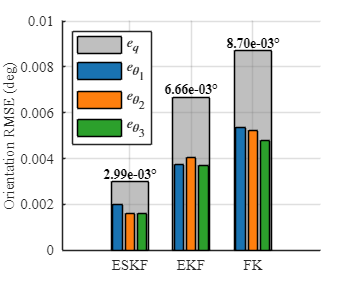


% --- Figure 2: Orientation RMSE ---
% fig_ori_rmse = figure('Name', 'Orientation RMSE Comparison', 'Position', [700, 100, 550, 450], 'Color', 'w');
fig_ori_rmse = figure('Name', 'Orientation RMSE Comparison', 'Position', fig_size, 'Color', 'w');
hold on;

ori_rmse_overall = [eskf_ori_rmse_overall, ekf_ori_rmse_overall, fk_ori_rmse_overall];
% Assuming ZYX order from calculation: Yaw=1, Pitch=2, Roll=3
ori_rmse_rpy = [eskf_ori_rmse_rpy; ekf_ori_rmse_rpy; fk_ori_rmse_rpy]'; % 3xN, [Yaw; Pitch; Roll] rows

% Plot overall RMSE bars
b_ori_overall = bar(x_indices, ori_rmse_overall, bar_width_overall, 'FaceColor', [0.5, 0.5, 0.5], 'FaceAlpha', 0.5, 'EdgeColor','k');

% Plotting order: Roll (index 3), Pitch (index 2), Yaw (index 1) to match RPY convention visually
b_roll = bar(x_indices - group_offset, ori_rmse_rpy(3,:), bar_width_detail, 'FaceColor', color1);  % Roll (index 3)
b_pitch= bar(x_indices,                ori_rmse_rpy(2,:), bar_width_detail, 'FaceColor', color2); % Pitch (index 2)
b_yaw  = bar(x_indices + group_offset, ori_rmse_rpy(1,:), bar_width_detail, 'FaceColor', color3);   % Yaw (index 1)

hold off;

set(gca, 'XTick', x_indices, 'XTickLabel', algorithms, 'FontSize', axisFontSize, 'FontName', fontName);
ylabel('Orientation RMSE (deg)', 'FontSize', plotFontSize, 'FontName', fontName);
grid on;
legend([b_ori_overall, b_roll, b_pitch, b_yaw], {'$e_{q}$', '$e_{\theta_1}$', '$e_{\theta_2}$', '$e_{\theta_3}$'}, ...
    'Location', 'northwest', 'FontSize', plotFontSize-1, 'FontName', fontName, 'Interpreter', 'latex');
ylim([0, max([ori_rmse_overall, ori_rmse_rpy(:)']) * 1.15]);

% Add numerical labels to OVERALL bars
for j = 1:length(ori_rmse_overall)
    text(x_indices(j), ori_rmse_overall(j), sprintf('%.2e°', ori_rmse_overall(j)), ...
         'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', ...
         'FontSize', axisFontSize - 1, 'FontName', fontName, 'Color', 'k', 'FontWeight', 'bold');
end

disp('Plotting 4 separate position and error comparison figures...');

Plotting 4 separate position and error comparison figures...



lineStyle1 = '-'; % ESKF Estimate/Error
lineStyle2 = '-'; % EKF Estimate/Error
lineStyle3 = '-'; % FK Estimate/Error
lineStyle4 = '--'; % Actual/Ground Truth Estimate
lineStyleBounds = ':'; % Sigma Bounds

lineWidth_main = 1.5;
lineWidth_bounds = 1.5;

% --- Extract Data & Align Timestamps ---
t_gt   = ground_truth_data.timestamps;
pos_gt = ground_truth_data.position;

t_eskf = est_states_ESKF.timestamp;
pos_eskf = est_states_ESKF.position;
P_hist_eskf = est_states_ESKF.P_history; % Assuming cell array or 3D matrix

t_ekf  = est_states_EKF.timestamp;
pos_ekf = est_states_EKF.position;
P_hist_ekf = est_states_EKF.P_history;  % Assuming cell array or 3D matrix

t_fk   = est_states_FK.timestamp;
pos_fk = est_states_FK.position;

% Interpolate estimates onto ground truth time
pos_eskf_interp = interp1(t_eskf, pos_eskf, t_gt, 'linear', 'extrap');
pos_ekf_interp  = interp1(t_ekf, pos_ekf, t_gt, 'linear', 'extrap');
pos_fk_interp   = interp1(t_fk, pos_fk, t_gt, 'linear', 'extrap');

% Select the first dimension (X position)
pos_x_gt   = pos_gt(:, 2);
pos_x_eskf = pos_eskf_interp(:, 2);
pos_x_ekf  = pos_ekf_interp(:, 2);
pos_x_fk   = pos_fk_interp(:, 2);

% --- Calculate Errors ---
error_x_eskf = pos_x_eskf - pos_x_gt;
error_x_ekf  = pos_x_ekf  - pos_x_gt;
error_x_fk   = pos_x_fk   - pos_x_gt;

% --- Calculate 3-Sigma Bounds ---
% ESKF
sigma_x_eskf = zeros(length(t_eskf), 1);
if iscell(P_hist_eskf)
    for i = 1:length(t_eskf)
        if ~isempty(P_hist_eskf{i}) && size(P_hist_eskf{i},1)>=1 && size(P_hist_eskf{i},2)>=1
             sigma_x_eskf(i) = sqrt(P_hist_eskf{i}(2, 2));
        else
             sigma_x_eskf(i) = NaN;
        end
    end
elseif isnumeric(P_hist_eskf) && ndims(P_hist_eskf) == 3
    if size(P_hist_eskf,1)>=1 && size(P_hist_eskf,2)>=1
        sigma_x_eskf = squeeze(sqrt(P_hist_eskf(2, 2, :)));
    else
        sigma_x_eskf(:) = NaN;
    end
else
    warning('ESKF P_history format not recognized (expected cell or 3D numeric). Skipping bounds.');
    sigma_x_eskf(:) = NaN;
end
bounds_3sigma_eskf_upper = +3 * sigma_x_eskf;
bounds_3sigma_eskf_lower = -3 * sigma_x_eskf;
bounds_3sigma_eskf_upper_interp = interp1(t_eskf, bounds_3sigma_eskf_upper, t_gt, 'linear', 'extrap');
bounds_3sigma_eskf_lower_interp = interp1(t_eskf, bounds_3sigma_eskf_lower, t_gt, 'linear', 'extrap');

% EKF
sigma_x_ekf = zeros(length(t_ekf), 1);
if iscell(P_hist_ekf)
    for i = 1:length(t_ekf)
         if ~isempty(P_hist_ekf{i}) && size(P_hist_ekf{i},1)>=1 && size(P_hist_ekf{i},2)>=1
             sigma_x_ekf(i) = sqrt(P_hist_ekf{i}(2, 2));
         else
             sigma_x_ekf(i) = NaN;
         end
    end
elseif isnumeric(P_hist_ekf) && ndims(P_hist_ekf) == 3
     if size(P_hist_ekf,1)>=1 && size(P_hist_ekf,2)>=1
        sigma_x_ekf = squeeze(sqrt(P_hist_ekf(2, 2, :)));
     else
        sigma_x_ekf(:) = NaN;
     end
else
    warning('EKF P_history format not recognized (expected cell or 3D numeric). Skipping bounds.');
    sigma_x_ekf(:) = NaN;
end
bounds_3sigma_ekf_upper = +3 * sigma_x_ekf;
bounds_3sigma_ekf_lower = -3 * sigma_x_ekf;
bounds_3sigma_ekf_upper_interp = interp1(t_ekf, bounds_3sigma_ekf_upper, t_gt, 'linear', 'extrap');
bounds_3sigma_ekf_lower_interp = interp1(t_ekf, bounds_3sigma_ekf_lower, t_gt, 'linear', 'extrap');

% --- Prerequisites ---
% Assume all variables from the previous step are available
% (t_gt, pos_x_gt, pos_x_eskf, etc.)
% Assume common plot variables like fontName, plotFontSize, axisFontSize exist
% Assume output variables like fileExtension, outputFormat, outputResolution exist

disp('Plotting X position comparison figure with local zoom...');

Plotting X position comparison figure with local zoom...


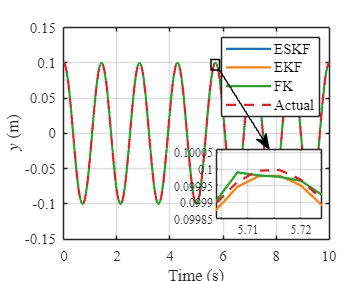

% --- Plotting Figure 1: Position Comparison ---
% fig1 = figure('Name', 'X Position Comparison with Inset', 'Position', [50, 500, 700, 450], 'Color', 'w'); % Slightly wider figure
fig1 = figure('Name', 'X Position Comparison with Inset', 'Position', fig_size, 'Color', 'w'); % Slightly wider figure

% axisFontSize = 10;
% Create main axes and store handle
% ax_main = axes('Position', [0.1, 0.12, 0.85, 0.8]); % Adjust main axes position slightly if needed
ax_main = axes('Position', [0.18, 0.15, 0.75, 0.75]);
hold(ax_main, 'on');
plot(ax_main, t_gt, pos_x_eskf, 'Color', color1, 'LineStyle', lineStyle1, 'LineWidth', lineWidth_main, 'DisplayName', 'ESKF');
plot(ax_main, t_gt, pos_x_ekf,  'Color', color2, 'LineStyle', lineStyle2, 'LineWidth', lineWidth_main, 'DisplayName', 'EKF');
plot(ax_main, t_gt, pos_x_fk,   'Color', color3, 'LineStyle', lineStyle3, 'LineWidth', lineWidth_main, 'DisplayName', 'FK');
plot(ax_main, t_gt, pos_x_gt,   'Color', color4, 'LineStyle', lineStyle4, 'LineWidth', lineWidth_main, 'DisplayName', 'Actual');
hold(ax_main, 'off');
grid(ax_main, 'on'); box(ax_main, 'on');
xlabel(ax_main, 'Time (s)', 'FontSize', axisFontSize, 'FontName', fontName);
ylabel(ax_main, '$y$ (m)', 'FontSize', axisFontSize, 'FontName', fontName, 'Interpreter', 'latex');
legend(ax_main, 'show', 'Location', 'northeast', 'FontSize', axisFontSize, 'FontName', fontName);
set(ax_main, 'FontSize', axisFontSize, 'FontName', fontName);
xlim(ax_main, [t_gt(1), t_gt(end)/2]); % Set desired x-limit for the main plot
% Let MATLAB determine Y limits initially, or set manually if needed
% ylim(ax_main, [min_y, max_y]);

% --- Define Inset Properties ---
inset_pos = [0.61, 0.22, 0.30, 0.25]; % Position of inset axes [left, bottom, width, height] in normalized units

% --- Define Separate Zoom Region Properties ---
% These control what data is shown in the inset
zoom_xlim = [5.704, 5.724];           % X-limits for the zoom region (data units)
zoom_ylim = [0.09985, 0.10006];        % Y-limits for the zoom region (data units)

% --- Define Separate Box Properties ---
% These directly control the black rectangle position (independent from zoom region)
box_x = 5.55;     % Left edge of box
box_y = 0.090;    % Bottom edge of box
box_w = 0.32;     % Width of box (5.87 - 5.55 = 0.32)
box_h = 0.015;    % Height of box (0.105 - 0.090 = 0.015)

% Draw the rectangle with explicit position
rectangle(ax_main, 'Position', [box_x, box_y, box_w, box_h], ...
          'EdgeColor', 'k', 'LineWidth', 1, 'LineStyle', '-');

% --- Create Inset Axes ---
ax_inset = axes('Position', inset_pos);
hold(ax_inset, 'on');
plot(ax_inset, t_gt, pos_x_eskf, 'Color', color1, 'LineStyle', lineStyle1, 'LineWidth', lineWidth_main);
plot(ax_inset, t_gt, pos_x_ekf,  'Color', color2, 'LineStyle', lineStyle2, 'LineWidth', lineWidth_main);
plot(ax_inset, t_gt, pos_x_fk,   'Color', color3, 'LineStyle', lineStyle3, 'LineWidth', lineWidth_main);
plot(ax_inset, t_gt, pos_x_gt,   'Color', color4, 'LineStyle', lineStyle4, 'LineWidth', lineWidth_main);
hold(ax_inset, 'off');
grid(ax_inset, 'on'); box(ax_inset, 'on');
xlim(ax_inset, zoom_xlim); % Apply zoom limits using separate zoom variables
ylim(ax_inset, zoom_ylim);
set(ax_inset, 'FontSize', axisFontSize-2, 'FontName', fontName);
% Optional: Remove tick labels from inset to reduce clutter
% set(ax_inset, 'XTickLabel', [], 'YTickLabel', []);

% --- Add Arrow Connecting Box and Inset (only left-top corner) ---
% Convert bounding box corners (data units) to normalized figure units
main_ax_pos = get(ax_main, 'Position');
main_xlim = get(ax_main, 'XLim');
main_ylim = get(ax_main, 'YLim');

% Calculate normalized coordinates of the bounding box right-bottom corner
x_norm_R = main_ax_pos(1) + main_ax_pos(3) * (box_x + box_w - main_xlim(1)) / diff(main_xlim);
y_norm_B = main_ax_pos(2) + main_ax_pos(4) * (box_y - main_ylim(1)) / diff(main_ylim);

% Inset axes mid-top position (normalized units)
inset_norm_M = inset_pos(1) + inset_pos(3)/2;  % 中点 = 左边界 + 宽度的一半
inset_norm_T = inset_pos(2) + inset_pos(4);    % 上边界

% Draw arrow from right-bottom of box to mid-top of inset
annotation(fig1, 'arrow', [x_norm_R, inset_norm_M], [y_norm_B, inset_norm_T], 'Color', 'k', 'LineWidth', 0.5);

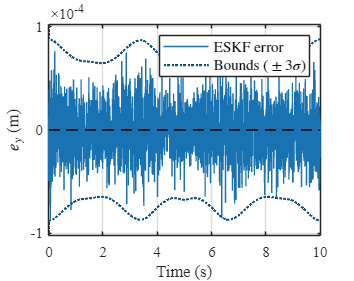

% --- Plotting Figure 2: ESKF Error and Bounds ---
% fig2 = figure('Name', 'ESKF X Position Error', 'Position', [660, 500, 600, 400], 'Color', 'w');
fig2 = figure('Name', 'ESKF X Position Error', 'Position', fig_size, 'Color', 'w');
hold on;
% Plot the error curve
plot(t_gt, error_x_eskf, 'Color', color1, 'LineStyle', lineStyle1, 'LineWidth', 0.5, 'DisplayName', 'ESKF error');

% Plot the upper and lower 3-sigma bounds; these two lines share one legend entry
plot(t_gt, bounds_3sigma_eskf_upper_interp, 'Color', color1*0.7, 'LineStyle', lineStyleBounds, 'LineWidth', lineWidth_bounds, 'DisplayName', 'Bounds ($\pm$3$\sigma$)');
plot(t_gt, bounds_3sigma_eskf_lower_interp, 'Color', color1*0.7, 'LineStyle', lineStyleBounds, 'LineWidth', lineWidth_bounds, 'HandleVisibility', 'off'); % Hide lower bound from legend

% Plot zero error line
plot(t_gt, zeros(size(t_gt)), 'k--', 'LineWidth', 0.5, 'HandleVisibility','off');
hold off;
grid on; box on;
xlabel('Time (s)', 'FontSize', axisFontSize, 'FontName', fontName);
ylabel('$e_y$ (m)', 'FontSize', axisFontSize, 'FontName', fontName, 'Interpreter', 'latex');
% title('ESKF Error (X) with 3\sigma Bounds', 'FontSize', plotFontSize, 'FontName', fontName, 'FontWeight', 'bold');

% Use LaTeX interpreter to ensure correct symbol display
legend('show', 'Location', 'northeast', 'FontSize', axisFontSize, 'FontName', fontName, 'Interpreter', 'latex');

set(gca, 'FontSize', axisFontSize, 'FontName', fontName);
ylim_val = max(abs([error_x_eskf; bounds_3sigma_eskf_upper_interp(10:end); bounds_3sigma_eskf_lower_interp(10:end)])) * 1.1;
ylim([-ylim_val, ylim_val]);
xlim([t_gt(1), t_gt(end)/2]);

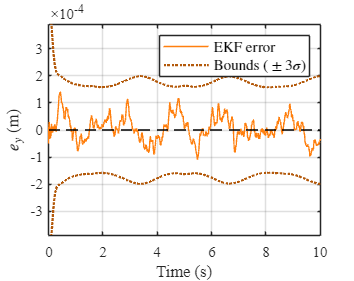


% --- Plotting Figure 3: EKF Error and Bounds ---
% fig3 = figure('Name', 'EKF X Position Error', 'Position', [50, 50, 600, 400], 'Color', 'w');
fig3 = figure('Name', 'EKF X Position Error', 'Position', fig_size, 'Color', 'w');
hold on;
plot(t_gt, error_x_ekf, 'Color', color2, 'LineStyle', lineStyle2, 'LineWidth', 0.5, 'DisplayName', 'EKF error');
h_upper = plot(t_gt, bounds_3sigma_ekf_upper_interp, 'Color', color2*0.7, 'LineStyle', lineStyleBounds, 'LineWidth', lineWidth_bounds, 'DisplayName', 'Bounds ($\pm$3$\sigma$)');
h_lower = plot(t_gt, bounds_3sigma_ekf_lower_interp, 'Color', color2*0.7, 'LineStyle', lineStyleBounds, 'LineWidth', lineWidth_bounds, 'HandleVisibility', 'off'); % 隐藏下边界的图例项

plot(t_gt, zeros(size(t_gt)), 'k--', 'LineWidth', 0.5, 'HandleVisibility','off'); % Zero error line
hold off;
grid on; box on;
xlabel('Time (s)', 'FontSize', axisFontSize, 'FontName', fontName);
ylabel('$e_y$ (m)', 'FontSize', axisFontSize, 'FontName', fontName, 'Interpreter', 'latex');
% title('EKF Error (X) with 3\sigma Bounds', 'FontSize', plotFontSize, 'FontName', fontName, 'FontWeight', 'bold');
legend('show', 'Location', 'northeast', 'FontSize', axisFontSize, 'FontName', fontName, 'Interpreter', 'latex');
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);
ylim_val = max(abs([error_x_ekf; bounds_3sigma_ekf_upper_interp(10:end); bounds_3sigma_ekf_lower_interp(10:end)]))*0.6;
ylim([-ylim_val, ylim_val]);
xlim([t_gt(1), t_gt(end)/2]);

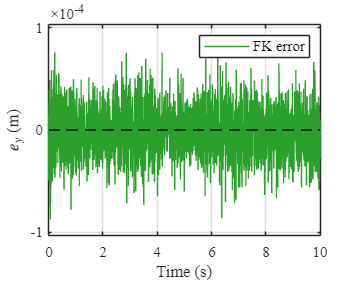

% --- Plotting Figure 4: FK Error ---
% fig4 = figure('Name', 'FK X Position Error', 'Position', [660, 50, 600, 400], 'Color', 'w');
fig4 = figure('Name', 'FK X Position Error', 'Position', fig_size, 'Color', 'w');
hold on;
plot(t_gt, error_x_fk, 'Color', color3, 'LineStyle', lineStyle3, 'LineWidth', 0.5, 'DisplayName', 'FK error');
plot(t_gt, zeros(size(t_gt)), 'k--', 'LineWidth', 0.5, 'HandleVisibility','off'); % Zero error line
hold off;
grid on; box on;
xlabel('Time (s)', 'FontSize', axisFontSize, 'FontName', fontName);
ylabel('$e_y$ (m)', 'FontSize', axisFontSize, 'FontName', fontName, 'Interpreter', 'latex');
% title('FK Error (X)', 'FontSize', plotFontSize, 'FontName', fontName, 'FontWeight', 'bold');
legend('show', 'Location', 'northeast', 'FontSize', axisFontSize, 'FontName', fontName); % Legend might not be needed
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);
ylim_val = max(abs(error_x_fk)) * 1.1;
if ~isnan(ylim_val) && ylim_val > 1e-6, ylim([-ylim_val, ylim_val]); end
xlim([t_gt(1), t_gt(end)/2]);

## Orientaion 1x4

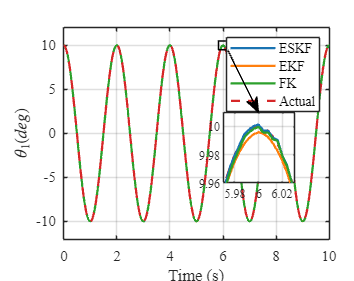

lineStyle1 = '-'; % ESKF Estimate
lineStyle2 = '-'; % EKF Estimate
lineStyle3 = '-'; % FK Estimate
lineStyle4 = '--'; % Actual/Ground Truth Estimate

lineWidth_main = 1.5;

% --- Extract Data & Align Timestamps ---
t_gt   = ground_truth_data.timestamps;
euler_gt = ground_truth_data.orientation; % Assuming Nx3 matrix [roll, pitch, yaw]

t_eskf = est_states_ESKF.timestamp;
euler_eskf = est_states_ESKF.euler; % Assuming Mx3

t_ekf  = est_states_EKF.timestamp;
euler_ekf = est_states_EKF.euler;  % Assuming Px3

t_fk   = est_states_FK.timestamp;
euler_fk = est_states_FK.euler;   % Assuming Qx3

% Interpolate estimates onto ground truth time
euler_eskf_interp = interp1(t_eskf, euler_eskf, t_gt, 'linear', 'extrap');
euler_ekf_interp  = interp1(t_ekf, euler_ekf, t_gt, 'linear', 'extrap');
euler_fk_interp   = interp1(t_fk, euler_fk, t_gt, 'linear', 'extrap');

% Extract first component (roll) only
roll_gt = euler_gt(:, 1);
roll_eskf = euler_eskf_interp(:, 1);
roll_ekf = euler_ekf_interp(:, 1);
roll_fk = euler_fk_interp(:, 1);

% --- Create Plot ---
% fig_euler = figure('Name', 'Roll Angle Tracking Comparison', 'Position', [100, 100, 600, 400], 'Color', 'w');
fig_euler = figure('Name', 'Roll Angle Tracking Comparison', 'Position', fig_size, 'Color', 'w');
% Create main axes and store handle
% ax_main = axes('Position', [0.1, 0.12, 0.85, 0.8]);
ax_main = axes('Position', [0.18, 0.15, 0.75, 0.75]);
hold(ax_main, 'on');
plot(ax_main, t_gt, roll_eskf, 'Color', color1, 'LineStyle', lineStyle1, 'LineWidth', lineWidth_main, 'DisplayName', 'ESKF');
plot(ax_main, t_gt, roll_ekf,  'Color', color2, 'LineStyle', lineStyle2, 'LineWidth', lineWidth_main, 'DisplayName', 'EKF');
plot(ax_main, t_gt, roll_fk,   'Color', color3, 'LineStyle', lineStyle3, 'LineWidth', lineWidth_main, 'DisplayName', 'FK');
plot(ax_main, t_gt, roll_gt,   'Color', color4, 'LineStyle', lineStyle4, 'LineWidth', lineWidth_main, 'DisplayName', 'Actual');
hold(ax_main, 'off');
grid(ax_main, 'on'); box(ax_main, 'on');
xlabel(ax_main, 'Time (s)', 'FontSize', axisFontSize, 'FontName', fontName);
ylabel(ax_main, '$\theta_1 (deg)$', 'FontSize', axisFontSize, 'FontName', fontName, 'interpreter', 'latex');
% title(ax_main, 'Roll Angle Tracking Performance', 'FontSize', plotFontSize, 'FontName', fontName, 'FontWeight', 'bold');
legend(ax_main, 'show', 'Location', 'northeast', 'FontSize', axisFontSize-1, 'FontName', fontName);
set(ax_main, 'FontSize', axisFontSize, 'FontName', fontName);
xlim(ax_main, [t_gt(1), t_gt(end)/2]);
ylim(ax_main, [min(roll_gt)*1.2, max(roll_gt)*1.2]);

% --- Define Inset Properties ---
inset_pos = [0.63, 0.35, 0.20, 0.25]; % Position of inset axes [left, bottom, width, height] in normalized units

% --- Define Separate Zoom Region Properties ---
% These control what data is shown in the inset - adjust these values based on your data
zoom_xlim = [5.97, 6.03];           % X-limits for the zoom region (data units)
zoom_ylim = [9.96, 10.01];          % Y-limits for the zoom region (data units)

% --- Define Separate Box Properties ---
% These directly control the black rectangle position (independent from zoom region)
box_x = 5.83;     % Left edge of box
box_y = 9.5;      % Bottom edge of box
box_w = 0.35;     % Width of box
box_h = 1.0;      % Height of box

% Draw the rectangle with explicit position
rectangle(ax_main, 'Position', [box_x, box_y, box_w, box_h], ...
          'EdgeColor', 'k', 'LineWidth', 1, 'LineStyle', '-');

% --- Create Inset Axes ---
ax_inset = axes('Position', inset_pos);
hold(ax_inset, 'on');
plot(ax_inset, t_gt, roll_gt,   'Color', color4, 'LineStyle', lineStyle4, 'LineWidth', lineWidth_main);
plot(ax_inset, t_gt, roll_eskf, 'Color', color1, 'LineStyle', lineStyle1, 'LineWidth', lineWidth_main);
plot(ax_inset, t_gt, roll_ekf,  'Color', color2, 'LineStyle', lineStyle2, 'LineWidth', lineWidth_main);
plot(ax_inset, t_gt, roll_fk,   'Color', color3, 'LineStyle', lineStyle3, 'LineWidth', lineWidth_main);
hold(ax_inset, 'off');
grid(ax_inset, 'on'); box(ax_inset, 'on');
xlim(ax_inset, zoom_xlim); % Apply zoom limits using separate zoom variables
ylim(ax_inset, zoom_ylim);
set(ax_inset, 'FontSize', axisFontSize-2, 'FontName', fontName);

% --- Add Arrow Connecting Box and Inset ---
% Convert bounding box corners (data units) to normalized figure units
main_ax_pos = get(ax_main, 'Position');
main_xlim = get(ax_main, 'XLim');
main_ylim = get(ax_main, 'YLim');

% Calculate normalized coordinates of the bounding box right-bottom corner
x_norm_R = main_ax_pos(1) + main_ax_pos(3) * (box_x + box_w - main_xlim(1)) / diff(main_xlim);
y_norm_B = main_ax_pos(2) + main_ax_pos(4) * (box_y - main_ylim(1)) / diff(main_ylim);

% Inset axes mid-top position (normalized units)
inset_norm_M = inset_pos(1) + inset_pos(3)/2;  % 中点 = 左边界 + 宽度的一半
inset_norm_T = inset_pos(2) + inset_pos(4);    % 上边界

% Draw arrow from right-bottom of box to mid-top of inset
annotation(fig_euler, 'arrow', [x_norm_R, inset_norm_M], [y_norm_B, inset_norm_T], 'Color', 'k', 'LineWidth', 0.5);

% Standard deviation of the first ESKF Euler angle error
eskf_euler_cov = zeros(size(t_gt));
for i = 1:length(t_gt)
    P_cov_R = est_states_ESKF.P_history{i}(7:9,7:9);
    Rot = est_states_ESKF.orientation{i};
    p_cov_Euler = rotation_matrix_cov_to_euler_cov(P_cov_R, Rot);
    eskf_euler_cov(i) = p_cov_Euler(1,1);
    eskf_euler_cov(i) = rad2deg(sqrt(eskf_euler_cov(i)));
end

% Standard deviation of the first EKF Euler angle error
ekf_euler_cov = zeros(size(t_gt));
for i = 1:length(t_gt)
    P_cov_q = est_states_EKF.P_history{i}(7:10,7:10);
    q = est_states_EKF.quaternion(i,:);
    p_cov_Euler = quaternion_cov_to_euler_cov(P_cov_q, q);
    ekf_euler_cov(i) = p_cov_Euler(1,1);
    ekf_euler_cov(i) = rad2deg(sqrt(ekf_euler_cov(i)));
end

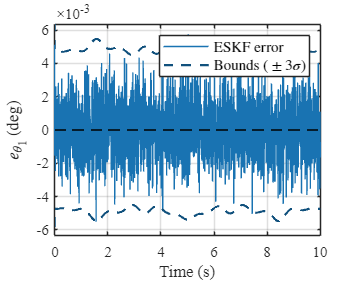

lineStyle1 = '-';          % ESKF estimate line style
lineStyle2 = '-';          % EKF estimate line style
lineStyle3 = '-';          % FK estimate line style
lineStyleBounds = '--';    % Bounds line style

% lineWidth_main = 0.5;
lineWidth_bounds = 1.5;

% Compute errors (estimated value minus ground truth)
error_roll_eskf = euler_eskf_interp(:, 1) - euler_gt(:, 1);
error_roll_ekf = euler_ekf_interp(:, 1) - euler_gt(:, 1);
error_roll_fk = euler_fk_interp(:, 1) - euler_gt(:, 1);

% Compute the ±3 standard deviation bounds
bounds_3sigma_eskf_upper = 3 * eskf_euler_cov;
bounds_3sigma_eskf_lower = -3 * eskf_euler_cov;

bounds_3sigma_ekf_upper = 3 * ekf_euler_cov;
bounds_3sigma_ekf_lower = -3 * ekf_euler_cov;

% --- Plot ESKF error and bounds ---
% fig_eskf = figure('Name', 'ESKF Roll Error', 'Position', [100, 500, 600, 400], 'Color', 'w');
fig_eskf = figure('Name', 'ESKF Roll Error', 'Position', fig_size, 'Color', 'w');
hold on;
% Plot error curve
plot(t_gt, error_roll_eskf, 'Color', color1, 'LineStyle', lineStyle1, 'LineWidth', 0.5, 'DisplayName', 'ESKF error');

% Plot bounds, both lines share one legend entry
h_upper = plot(t_gt, bounds_3sigma_eskf_upper, 'Color', color1*0.7, 'LineStyle', lineStyleBounds, 'LineWidth', lineWidth_bounds, 'DisplayName', 'Bounds ($\pm$3$\sigma$)');
h_lower = plot(t_gt, bounds_3sigma_eskf_lower, 'Color', color1*0.7, 'LineStyle', lineStyleBounds, 'LineWidth', lineWidth_bounds, 'HandleVisibility', 'off'); % Hide lower bound from legend

% Plot zero error line
plot(t_gt, zeros(size(t_gt)), 'k--', 'LineWidth', 0.5, 'HandleVisibility','off');
hold off;
grid on; box on;
xlabel('Time (s)', 'FontSize', axisFontSize, 'FontName', fontName);
ylabel('$e_{\theta_1}$ (deg)', 'FontSize', axisFontSize, 'FontName', fontName, 'Interpreter', 'latex');
% title('ESKF Roll Error with 3$\sigma$ Bounds', 'FontSize', plotFontSize, 'FontName', fontName, 'FontWeight', 'bold', 'Interpreter', 'latex');

% Use LaTeX interpreter to ensure correct symbol display
legend('show', 'Location', 'northeast', 'FontSize', axisFontSize, 'FontName', fontName, 'Interpreter', 'latex');

set(gca, 'FontSize', axisFontSize, 'FontName', fontName);
ylim_val = max(abs([error_roll_eskf; bounds_3sigma_eskf_upper(10:end); bounds_3sigma_eskf_lower(10:end)])) * 1.1;
ylim([-ylim_val, ylim_val]);
xlim([t_gt(1), t_gt(end)/2]);

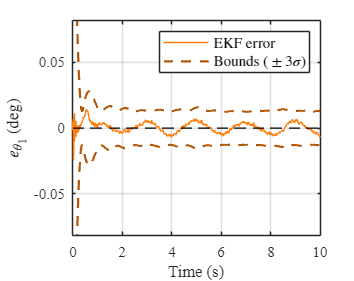

% --- Plot EKF error and bounds ---
% fig_ekf = figure('Name', 'EKF Roll Error', 'Position', [100, 50, 600, 400], 'Color', 'w');
fig_ekf = figure('Name', 'EKF Roll Error', 'Position', fig_size, 'Color', 'w');
hold on;
% Plot error curve
plot(t_gt, error_roll_ekf, 'Color', color2, 'LineStyle', lineStyle2, 'LineWidth', 0.5, 'DisplayName', 'EKF error');

% Plot bounds
h_upper = plot(t_gt, bounds_3sigma_ekf_upper, 'Color', color2*0.7, 'LineStyle', lineStyleBounds, 'LineWidth', lineWidth_bounds, 'DisplayName', 'Bounds ($\pm$3$\sigma$)');
h_lower = plot(t_gt, bounds_3sigma_ekf_lower, 'Color', color2*0.7, 'LineStyle', lineStyleBounds, 'LineWidth', lineWidth_bounds, 'HandleVisibility', 'off');

% Plot zero error line
plot(t_gt, zeros(size(t_gt)), 'k--', 'LineWidth', 0.5, 'HandleVisibility','off');
hold off;
grid on; box on;
xlabel('Time (s)', 'FontSize', axisFontSize, 'FontName', fontName);
ylabel('$e_{\theta_1}$ (deg)', 'FontSize', axisFontSize, 'FontName', fontName, 'Interpreter', 'latex');
% title('EKF Roll Error with 3$\sigma$ Bounds', 'FontSize', plotFontSize, 'FontName', fontName, 'FontWeight', 'bold', 'Interpreter', 'latex');

legend('show', 'Location', 'northeast', 'FontSize', axisFontSize, 'FontName', fontName, 'Interpreter', 'latex');

set(gca, 'FontSize', axisFontSize, 'FontName', fontName);
ylim_val = max(abs([error_roll_ekf; bounds_3sigma_ekf_upper(20:end); bounds_3sigma_ekf_lower(20:end)])) * 0.5;
ylim([-ylim_val, ylim_val]);
xlim([t_gt(1), t_gt(end)/2]);

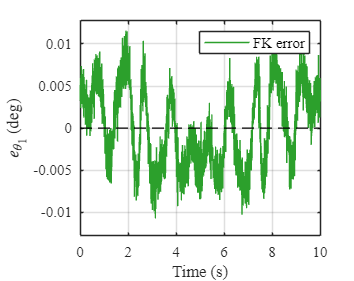

% --- Plot FK error (no standard deviation bounds) ---
% fig_fk = figure('Name', 'FK Roll Error', 'Position', [720, 500, 600, 400], 'Color', 'w');
fig_fk = figure('Name', 'FK Roll Error', 'Position', fig_size, 'Color', 'w');
hold on;
% Plot error curve
plot(t_gt, error_roll_fk, 'Color', color3, 'LineStyle', lineStyle3, 'LineWidth', 0.5, 'DisplayName', 'FK error');

% Plot zero error line
plot(t_gt, zeros(size(t_gt)), 'k--', 'LineWidth', 0.5, 'HandleVisibility','off');
hold off;
grid on; box on;
xlabel('Time (s)', 'FontSize', axisFontSize, 'FontName', fontName);
ylabel('$e_{\theta_1}$ (deg)', 'FontSize', axisFontSize, 'FontName', fontName, 'Interpreter', 'latex');
% title('FK Roll Error', 'FontSize', plotFontSize, 'FontName', fontName, 'FontWeight', 'bold');

legend('show', 'Location', 'northeast', 'FontSize', axisFontSize, 'FontName', fontName);

set(gca, 'FontSize', axisFontSize, 'FontName', fontName);
ylim_val = max(abs(error_roll_fk)) * 1.1;
ylim([-ylim_val, ylim_val]);
xlim([t_gt(1), t_gt(end)/2]);

## Velocity Error 1x4  With Cov

disp('Plotting Velocity Tracking Curve...');

Plotting Velocity Tracking Curve...


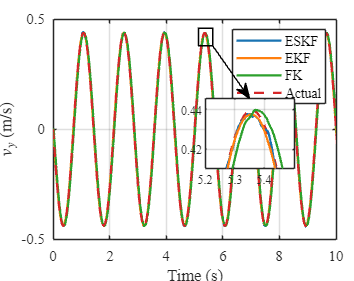

lineStyle1 = '-'; % ESKF Estimate
lineStyle2 = '-'; % EKF Estimate
lineStyle3 = '-'; % FK Estimate
lineStyle4 = '--'; % Actual/Ground Truth Estimate

lineWidth_main = 1.5;

% --- Extract Data & Align Timestamps ---
t_gt   = ground_truth_data.timestamps;
vel_gt = ground_truth_data.velocity; % Assuming Nx3 matrix [Vx, Vy, Vz]

t_eskf = est_states_ESKF.timestamp;
vel_eskf = est_states_ESKF.velocity; % Assuming Mx3

t_ekf  = est_states_EKF.timestamp;
vel_ekf = est_states_EKF.velocity;  % Assuming Px3

t_fk   = est_states_FK.timestamp;
vel_fk = est_states_FK.velocity;   % Assuming Qx3

% Interpolate estimates onto ground truth time
vel_eskf_interp = interp1(t_eskf, vel_eskf, t_gt, 'linear', 'extrap');
vel_ekf_interp  = interp1(t_ekf, vel_ekf, t_gt, 'linear', 'extrap');
vel_fk_interp   = interp1(t_fk, vel_fk, t_gt, 'linear', 'extrap');

% Extract Y components only
vel_y_gt = vel_gt(:, 2);
vel_y_eskf = vel_eskf_interp(:, 2);
vel_y_ekf = vel_ekf_interp(:, 2);
vel_y_fk = vel_fk_interp(:, 2);

% --- Create Plot ---
% fig_vel = figure('Name', 'Y-Velocity Tracking Comparison', 'Position', [100, 100, 600, 400], 'Color', 'w');
fig_vel = figure('Name', 'Y-Velocity Tracking Comparison', 'Position', fig_size, 'Color', 'w');
% Create main axes and store handle
% ax_main = axes('Position', [0.15, 0.15, 0.78, 0.78]);
ax_main = axes('Position', [0.15, 0.15, 0.80, 0.78]);
hold(ax_main, 'on');
plot(ax_main, t_gt, vel_y_eskf, 'Color', color1, 'LineStyle', lineStyle1, 'LineWidth', lineWidth_main, 'DisplayName', 'ESKF');
plot(ax_main, t_gt, vel_y_ekf,  'Color', color2, 'LineStyle', lineStyle2, 'LineWidth', lineWidth_main, 'DisplayName', 'EKF');
plot(ax_main, t_gt, vel_y_fk,   'Color', color3, 'LineStyle', lineStyle3, 'LineWidth', lineWidth_main, 'DisplayName', 'FK');
plot(ax_main, t_gt, vel_y_gt,   'Color', color4, 'LineStyle', lineStyle4, 'LineWidth', lineWidth_main, 'DisplayName', 'Actual');
hold(ax_main, 'off');
grid(ax_main, 'on'); box(ax_main, 'on');
xlabel(ax_main, 'Time (s)', 'FontSize', axisFontSize, 'FontName', fontName);
ylabel(ax_main, '$v_y$ (m/s)', 'FontSize', axisFontSize, 'FontName', fontName, 'Interpreter',  'latex');
% title(ax_main, 'Y-Direction Velocity Tracking Performance', 'FontSize', plotFontSize, 'FontName', fontName, 'FontWeight', 'bold');
legend(ax_main, 'show', 'Location', 'northeast', 'FontSize', axisFontSize-1, 'FontName', fontName);
set(ax_main, 'FontSize', axisFontSize, 'FontName', fontName);
xlim(ax_main, [t_gt(1), t_gt(end)/2]);

% --- Define Inset Properties ---
inset_pos = [0.58, 0.40, 0.25, 0.25]; % Position of inset axes [left, bottom, width, height] in normalized units

% --- Define Separate Zoom Region Properties ---
% These control what data is shown in the inset - adjust these values based on your data
zoom_xlim = [5.20, 5.50];           % X-limits for the zoom region (data units)
zoom_ylim = [0.41, 0.446];        % Y-limits for the zoom region (data units)

% --- Define Separate Box Properties ---
% These directly control the black rectangle position (independent from zoom region)
box_x = 5.14;     % Left edge of box
box_y = 0.38;   % Bottom edge of box
box_w = 0.5;     % Width of box
box_h = 0.08;    % Height of box

% Draw the rectangle with explicit position
rectangle(ax_main, 'Position', [box_x, box_y, box_w, box_h], ...
          'EdgeColor', 'k', 'LineWidth', 1, 'LineStyle', '-');

% --- Create Inset Axes ---
ax_inset = axes('Position', inset_pos);
hold(ax_inset, 'on');
plot(ax_inset, t_gt, vel_y_gt,   'Color', color4, 'LineStyle', lineStyle4, 'LineWidth', lineWidth_main);
plot(ax_inset, t_gt, vel_y_eskf, 'Color', color1, 'LineStyle', lineStyle1, 'LineWidth', lineWidth_main);
plot(ax_inset, t_gt, vel_y_ekf,  'Color', color2, 'LineStyle', lineStyle2, 'LineWidth', lineWidth_main);
plot(ax_inset, t_gt, vel_y_fk,   'Color', color3, 'LineStyle', lineStyle3, 'LineWidth', lineWidth_main);
hold(ax_inset, 'off');
grid(ax_inset, 'on'); box(ax_inset, 'on');
xlim(ax_inset, zoom_xlim); % Apply zoom limits using separate zoom variables
ylim(ax_inset, zoom_ylim);
set(ax_inset, 'FontSize', axisFontSize-2, 'FontName', fontName);

% --- Add Arrow Connecting Box and Inset ---
% Convert bounding box corners (data units) to normalized figure units
main_ax_pos = get(ax_main, 'Position');
main_xlim = get(ax_main, 'XLim');
main_ylim = get(ax_main, 'YLim');

% Calculate normalized coordinates of the bounding box right-bottom corner
x_norm_R = main_ax_pos(1) + main_ax_pos(3) * (box_x + box_w - main_xlim(1)) / diff(main_xlim);
y_norm_B = main_ax_pos(2) + main_ax_pos(4) * (box_y - main_ylim(1)) / diff(main_ylim);

% Inset axes mid-top position (normalized units)
inset_norm_M = inset_pos(1) + inset_pos(3)/2; 
inset_norm_T = inset_pos(2) + inset_pos(4);  

% Draw arrow from right-bottom of box to mid-top of inset
annotation(fig_vel, 'arrow', [x_norm_R, inset_norm_M], [y_norm_B, inset_norm_T], 'Color', 'k', 'LineWidth', 0.5);

% Standard deviation of the first ESKF velocity error
eskf_vel_cov = zeros(size(t_gt));
for i = 1:length(t_gt)
    P_cov_R = est_states_ESKF.P_history{i}(4:6,4:6); % Velocity covariance matrix
    eskf_vel_cov(i) = P_cov_R(2,2);                  % Variance of the first velocity component
    eskf_vel_cov(i) = sqrt(eskf_vel_cov(i));         % Standard deviation
end

% Standard deviation of the first EKF velocity error
ekf_vel_cov = zeros(size(t_gt));
for i = 1:length(t_gt)
    P_cov_R = est_states_EKF.P_history{i}(4:6,4:6);  % Velocity covariance matrix
    ekf_vel_cov(i) = P_cov_R(2,2);                   % Variance of the first velocity component
    ekf_vel_cov(i) = sqrt(ekf_vel_cov(i));           % Standard deviation
end

% --- Plot velocity error curves ---
disp('Plotting velocity error curves...');

Plotting velocity error curves...



lineStyle1 = '-';      % ESKF estimate line style
lineStyle2 = '-';      % EKF estimate line style
lineStyle3 = '-';      % FK estimate line style
lineStyle4 = '--';     % Ground truth line style
lineStyleBounds = '--';% Bounds line style

lineWidth_main = 0.5;
lineWidth_bounds = 1.5;

% --- Extract Data & Align Timestamps ---
t_gt   = ground_truth_data.timestamps;
vel_gt = ground_truth_data.velocity;

t_eskf = est_states_ESKF.timestamp;
vel_eskf = est_states_ESKF.velocity;

t_ekf  = est_states_EKF.timestamp;
vel_ekf = est_states_EKF.velocity;

t_fk   = est_states_FK.timestamp;
vel_fk = est_states_FK.velocity; 

% Interpolate estimated velocities onto ground truth timestamps
vel_eskf_interp = interp1(t_eskf, vel_eskf, t_gt, 'linear', 'extrap');
vel_ekf_interp  = interp1(t_ekf, vel_ekf, t_gt, 'linear', 'extrap');
vel_fk_interp   = interp1(t_fk, vel_fk, t_gt, 'linear', 'extrap');

% Also interpolate standard deviation data
eskf_vel_cov_interp = interp1(t_eskf, eskf_vel_cov, t_gt, 'linear', 'extrap');
ekf_vel_cov_interp = interp1(t_ekf, ekf_vel_cov, t_gt, 'linear', 'extrap');

% Extract Y-axis (second column) component
vel_y_gt = vel_gt(:, 2);
vel_y_eskf = vel_eskf_interp(:, 2);
vel_y_ekf = vel_ekf_interp(:, 2);
vel_y_fk = vel_fk_interp(:, 2);

% Compute errors (estimate minus ground truth)
error_vel_y_eskf = vel_y_eskf - vel_y_gt;
error_vel_y_ekf = vel_y_ekf - vel_y_gt;
error_vel_y_fk = vel_y_fk - vel_y_gt;

% Compute ±3 standard deviation bounds
bounds_3sigma_eskf_upper = 3 * eskf_vel_cov;
bounds_3sigma_eskf_lower = -3 * eskf_vel_cov;

bounds_3sigma_ekf_upper = 3 * ekf_vel_cov;
bounds_3sigma_ekf_lower = -3 * ekf_vel_cov;

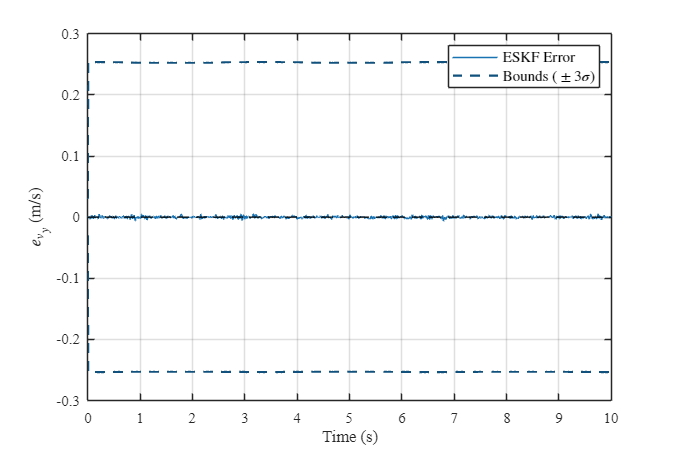

% --- Plot ESKF velocity error and bounds ---
fig_eskf_vel = figure('Name', 'ESKF Y-Velocity Error', 'Position', [100, 500, 600, 400], 'Color', 'w');
hold on;
% Plot error curve
plot(t_gt, error_vel_y_eskf, 'Color', color1, 'LineStyle', lineStyle1, 'LineWidth', 0.5, 'DisplayName', 'ESKF Error');
% plot(t_gt, error_vel_y_ekf, 'Color', color2, 'LineStyle', lineStyle2, 'LineWidth', 0.5, 'DisplayName', 'EKF Error');

% Plot bounds, these two lines share one legend entry
h_upper = plot(t_gt, bounds_3sigma_eskf_upper, 'Color', color1*0.7, 'LineStyle', lineStyleBounds, 'LineWidth', lineWidth_bounds, 'DisplayName', 'Bounds ($\pm$3$\sigma$)');
h_lower = plot(t_gt, bounds_3sigma_eskf_lower, 'Color', color1*0.7, 'LineStyle', lineStyleBounds, 'LineWidth', lineWidth_bounds, 'HandleVisibility', 'off'); % Hide lower bound from legend

% Plot zero error line
plot(t_gt, zeros(size(t_gt)), 'k--', 'LineWidth', 0.5, 'HandleVisibility','off');
hold off;
grid on; box on;
xlabel('Time (s)', 'FontSize', axisFontSize, 'FontName', fontName);
ylabel('$e_{v_y}$ (m/s)', 'FontSize', axisFontSize, 'FontName', fontName, 'Interpreter', 'latex');
% title('ESKF Y-Velocity Error with 3$\sigma$ Bounds', 'FontSize', plotFontSize, 'FontName', fontName, 'FontWeight', 'bold', 'Interpreter', 'latex');

% Use LaTeX interpreter to ensure correct symbol display
legend('show', 'Location', 'northeast', 'FontSize', axisFontSize, 'FontName', fontName, 'Interpreter', 'latex');

set(gca, 'FontSize', axisFontSize, 'FontName', fontName);
% ylim_val = max(abs([error_vel_y_eskf; bounds_3sigma_eskf_upper(10:end); bounds_3sigma_eskf_lower(10:end)])) * 1.1;
% ylim([-ylim_val, ylim_val]);
xlim([t_gt(1), t_gt(end)/2]);

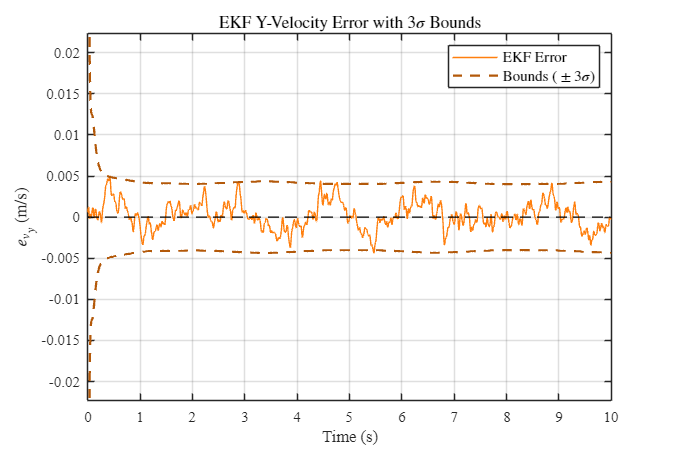

% --- Plot EKF velocity error and bounds ---
fig_ekf_vel = figure('Name', 'EKF Y-Velocity Error', 'Position', [100, 50, 600, 400], 'Color', 'w');
hold on;
% Plot error curve
plot(t_gt, error_vel_y_ekf, 'Color', color2, 'LineStyle', lineStyle2, 'LineWidth', 0.5, 'DisplayName', 'EKF Error');

% Plot bounds
h_upper = plot(t_gt, bounds_3sigma_ekf_upper, 'Color', color2*0.7, 'LineStyle', lineStyleBounds, 'LineWidth', lineWidth_bounds, 'DisplayName', 'Bounds ($\pm$3$\sigma$)');
h_lower = plot(t_gt, bounds_3sigma_ekf_lower, 'Color', color2*0.7, 'LineStyle', lineStyleBounds, 'LineWidth', lineWidth_bounds, 'HandleVisibility', 'off');

% Plot zero error line
plot(t_gt, zeros(size(t_gt)), 'k--', 'LineWidth', 0.5, 'HandleVisibility','off');
hold off;
grid on; box on;
xlabel('Time (s)', 'FontSize', axisFontSize, 'FontName', fontName);
ylabel('$e_{v_y}$ (m/s)', 'FontSize', axisFontSize, 'FontName', fontName, 'Interpreter', 'latex');
title('EKF Y-Velocity Error with 3$\sigma$ Bounds', 'FontSize', plotFontSize, 'FontName', fontName, 'FontWeight', 'bold', 'Interpreter', 'latex');

legend('show', 'Location', 'northeast', 'FontSize', axisFontSize, 'FontName', fontName, 'Interpreter', 'latex');

set(gca, 'FontSize', axisFontSize, 'FontName', fontName);
ylim_val = max(abs([error_vel_y_ekf; bounds_3sigma_ekf_upper(10:end); bounds_3sigma_ekf_lower(10:end)])) * 1.1;
ylim([-ylim_val, ylim_val]);
xlim([t_gt(1), t_gt(end)/2]);

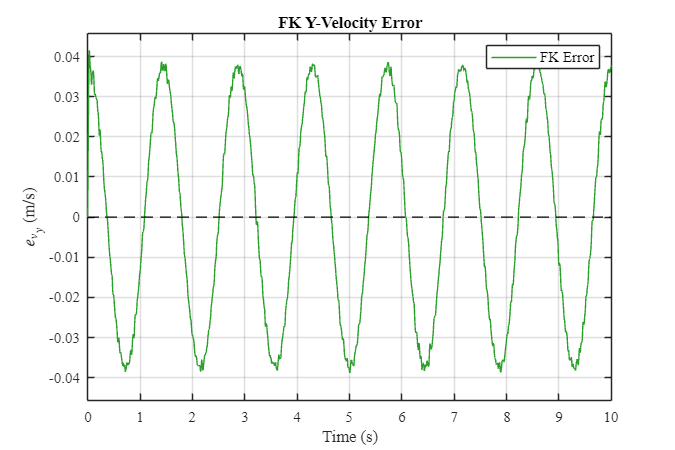

% --- Plot FK velocity error (no standard deviation bounds) ---
fig_fk_vel = figure('Name', 'FK Y-Velocity Error', 'Position', [720, 500, 600, 400], 'Color', 'w');
hold on;
% Plot error curve
plot(t_gt, error_vel_y_fk, 'Color', color3, 'LineStyle', lineStyle3, 'LineWidth', 0.5, 'DisplayName', 'FK Error');

% Plot zero error line
plot(t_gt, zeros(size(t_gt)), 'k--', 'LineWidth', 0.5, 'HandleVisibility','off');
hold off;
grid on; box on;
xlabel('Time (s)', 'FontSize', axisFontSize, 'FontName', fontName);
ylabel('$e_{v_y}$ (m/s)', 'FontSize', axisFontSize, 'FontName', fontName, 'Interpreter', 'latex');
title('FK Y-Velocity Error', 'FontSize', plotFontSize, 'FontName', fontName, 'FontWeight', 'bold');

legend('show', 'Location', 'northeast', 'FontSize', axisFontSize, 'FontName', fontName);

set(gca, 'FontSize', axisFontSize, 'FontName', fontName);
ylim_val = max(abs(error_vel_y_fk)) * 1.1;
ylim([-ylim_val, ylim_val]);
xlim([t_gt(1), t_gt(end)/2]);

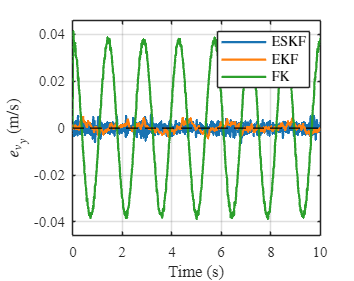

% --- Plot combined Y-velocity error curves for all three filters ---
fig_combined = figure('Name', 'Combined Y-Velocity Errors', 'Position', [700, 300, 800, 500], 'Color', 'w');
fig_combined = figure('Name', 'Combined Y-Velocity Errors', 'Position', fig_size, 'Color', 'w');
hold on;

% Plot error curves for all three filters
plot(t_gt, error_vel_y_eskf, 'Color', color1, 'LineStyle', lineStyle1, 'LineWidth', 1.5, 'DisplayName', 'ESKF');
plot(t_gt, error_vel_y_ekf, 'Color', color2, 'LineStyle', lineStyle2, 'LineWidth', 1.5, 'DisplayName', 'EKF');
plot(t_gt, error_vel_y_fk, 'Color', color3, 'LineStyle', lineStyle3, 'LineWidth', 1.5, 'DisplayName', 'FK');

% % Plot ESKF bounds (optional)
% h_upper_eskf = plot(t_gt, bounds_3sigma_eskf_upper, 'Color', color1*0.7, 'LineStyle', lineStyleBounds, 'LineWidth', lineWidth_bounds, 'DisplayName', 'ESKF Bounds ($\pm$3$\sigma$)');
% h_lower_eskf = plot(t_gt, bounds_3sigma_eskf_lower, 'Color', color1*0.7, 'LineStyle', lineStyleBounds, 'LineWidth', lineWidth_bounds, 'HandleVisibility', 'off');
% 
% % Plot EKF bounds (optional)
% h_upper_ekf = plot(t_gt, bounds_3sigma_ekf_upper, 'Color', color2*0.7, 'LineStyle', lineStyleBounds, 'LineWidth', lineWidth_bounds, 'DisplayName', 'EKF Bounds ($\pm$3$\sigma$)');
% h_lower_ekf = plot(t_gt, bounds_3sigma_ekf_lower, 'Color', color2*0.7, 'LineStyle', lineStyleBounds, 'LineWidth', lineWidth_bounds, 'HandleVisibility', 'off');

% Plot zero error line
plot(t_gt, zeros(size(t_gt)), 'k--', 'LineWidth', 0.5, 'HandleVisibility', 'off');

hold off;
grid on; box on;
xlabel('Time (s)', 'FontSize', axisFontSize, 'FontName', fontName);
ylabel('$e_{v_y}$ (m/s)', 'FontSize', axisFontSize, 'FontName', fontName, 'Interpreter', 'latex');
% title('Comparison of Y-Velocity Errors with 3$\sigma$ Bounds', 'FontSize', plotFontSize, 'FontName', fontName, 'FontWeight', 'bold', 'Interpreter', 'latex');

% Use LaTeX interpreter to ensure correct display of symbols
legend('show', 'Location', 'northeast', 'FontSize', axisFontSize-1, 'FontName', fontName, 'Interpreter', 'latex', 'NumColumns', 1);

set(gca, 'FontSize', axisFontSize, 'FontName', fontName);

% Compute appropriate y-axis limits
all_errors = [error_vel_y_eskf; error_vel_y_ekf; error_vel_y_fk];
% all_bounds = [bounds_3sigma_eskf_upper; bounds_3sigma_eskf_lower; 
%               bounds_3sigma_ekf_upper; bounds_3sigma_ekf_lower];

ylim_val = max(abs(all_errors)) * 1.1;
ylim([-ylim_val, ylim_val]);
xlim([t_gt(1), t_gt(end)/2]);

%% Plot velocity RMSE comparison figure

disp('Plotting velocity RMSE comparison figure...');

Plotting velocity RMSE comparison figure...


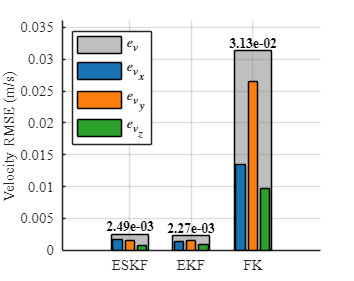


% --- Extract velocity components in XYZ directions ---
% X-direction velocity
vel_x_gt = vel_gt(:, 1);
vel_x_eskf = vel_eskf_interp(:, 1);
vel_x_ekf = vel_ekf_interp(:, 1);
vel_x_fk = vel_fk_interp(:, 1);

% Y-direction velocity
vel_y_gt = vel_gt(:, 2);
vel_y_eskf = vel_eskf_interp(:, 2);
vel_y_ekf = vel_ekf_interp(:, 2);
vel_y_fk = vel_fk_interp(:, 2);

% Z-direction velocity
vel_z_gt = vel_gt(:, 3);
vel_z_eskf = vel_eskf_interp(:, 3);
vel_z_ekf = vel_ekf_interp(:, 3);
vel_z_fk = vel_fk_interp(:, 3);

% --- Calculate velocity errors ---
% X velocity error
error_vel_x_eskf = vel_x_eskf - vel_x_gt;
error_vel_x_ekf = vel_x_ekf - vel_x_gt;
error_vel_x_fk = vel_x_fk - vel_x_gt;

% Y velocity error
error_vel_y_eskf = vel_y_eskf - vel_y_gt;
error_vel_y_ekf = vel_y_ekf - vel_y_gt;
error_vel_y_fk = vel_y_fk - vel_y_gt;

% Z velocity error
error_vel_z_eskf = vel_z_eskf - vel_z_gt;
error_vel_z_ekf = vel_z_ekf - vel_z_gt;
error_vel_z_fk = vel_z_fk - vel_z_gt;

% --- Calculate RMSE ---
% ESKF velocity RMSE
eskf_vel_x_rmse = sqrt(mean(error_vel_x_eskf.^2));
eskf_vel_y_rmse = sqrt(mean(error_vel_y_eskf.^2));
eskf_vel_z_rmse = sqrt(mean(error_vel_z_eskf.^2));
eskf_vel_rmse_xyz = [eskf_vel_x_rmse, eskf_vel_y_rmse, eskf_vel_z_rmse];
% Overall velocity RMSE (root mean square error over all three axes)
eskf_vel_rmse = sqrt(mean(error_vel_x_eskf.^2 + error_vel_y_eskf.^2 + error_vel_z_eskf.^2));

% EKF velocity RMSE
ekf_vel_x_rmse = sqrt(mean(error_vel_x_ekf.^2));
ekf_vel_y_rmse = sqrt(mean(error_vel_y_ekf.^2));
ekf_vel_z_rmse = sqrt(mean(error_vel_z_ekf.^2));
ekf_vel_rmse_xyz = [ekf_vel_x_rmse, ekf_vel_y_rmse, ekf_vel_z_rmse];
% Overall velocity RMSE
ekf_vel_rmse = sqrt(mean(error_vel_x_ekf.^2 + error_vel_y_ekf.^2 + error_vel_z_ekf.^2));

% FK velocity RMSE
fk_vel_x_rmse = sqrt(mean(error_vel_x_fk.^2));
fk_vel_y_rmse = sqrt(mean(error_vel_y_fk.^2));
fk_vel_z_rmse = sqrt(mean(error_vel_z_fk.^2));
fk_vel_rmse_xyz = [fk_vel_x_rmse, fk_vel_y_rmse, fk_vel_z_rmse];
% Overall velocity RMSE
fk_vel_rmse = sqrt(mean(error_vel_x_fk.^2 + error_vel_y_fk.^2 + error_vel_z_fk.^2));

% --- Plot velocity RMSE comparison ---
% Set plotting parameters
algorithms = {'ESKF', 'EKF', 'FK'};
x_indices = 1:length(algorithms);
bar_width_overall = 0.6;
bar_width_detail = 0.15;
group_offset = 0.2;

% Create figure
% fig_vel_rmse = figure('Name', 'Velocity RMSE Comparison', 'Position', [100, 100, 550, 450], 'Color', 'w');
fig_vel_rmse = figure('Name', 'Velocity RMSE Comparison', 'Position', fig_size, 'Color', 'w');

hold on;

vel_rmse_overall = [eskf_vel_rmse, ekf_vel_rmse, fk_vel_rmse];
vel_rmse_xyz = [eskf_vel_rmse_xyz; ekf_vel_rmse_xyz; fk_vel_rmse_xyz]'; % 3xN

% Plot overall RMSE bars
b_vel_overall = bar(x_indices, vel_rmse_overall, bar_width_overall, 'FaceColor', [0.5, 0.5, 0.5], 'FaceAlpha', 0.5, 'EdgeColor','k');

% Plot XYZ component bars
b_x = bar(x_indices - group_offset, vel_rmse_xyz(1,:), bar_width_detail, 'FaceColor', color1);
b_y = bar(x_indices,                vel_rmse_xyz(2,:), bar_width_detail, 'FaceColor', color2);
b_z = bar(x_indices + group_offset, vel_rmse_xyz(3,:), bar_width_detail, 'FaceColor', color3);

hold off;

set(gca, 'XTick', x_indices, 'XTickLabel', algorithms, 'FontSize', axisFontSize, 'FontName', fontName);
ylabel('Velocity RMSE (m/s)', 'FontSize', plotFontSize, 'FontName', fontName);
grid on;
legend([b_vel_overall, b_x, b_y, b_z], {'$e_{v}$', '$e_{v_x}$', '$e_{v_y}$', '$e_{v_z}$'}, ...
    'Location', 'northwest', 'FontSize', plotFontSize-1, 'FontName', fontName, 'Interpreter', 'latex');
ylim([0, max([vel_rmse_overall, vel_rmse_xyz(:)']) * 1.15]);

% Add numerical labels to overall RMSE bars (scientific notation)
for j = 1:length(vel_rmse_overall)
    text(x_indices(j), vel_rmse_overall(j), sprintf('%.2e', vel_rmse_overall(j)), ...
         'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', ...
         'FontSize', axisFontSize - 1, 'FontName', fontName, 'Color', 'k', 'FontWeight', 'bold');
end

%% Plot angular velocity RMSE comparison figure

disp('Plotting angular velocity RMSE comparison figure...');

Plotting angular velocity RMSE comparison figure...


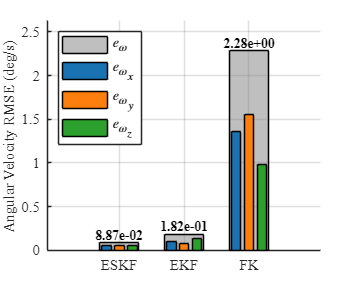


% --- Extract angular velocity data ---
t_gt = ground_truth_data.timestamps;
omega_gt = ground_truth_data.angular_velocity;

t_eskf = est_states_ESKF.timestamp;
omega_eskf = est_states_ESKF.angular_velocity;

t_ekf = est_states_EKF.timestamp;
omega_ekf = est_states_EKF.angular_velocity;

t_fk = est_states_FK.timestamp;
omega_fk = est_states_FK.angular_velocity;

% --- Ensure all data is on the same time axis (interpolate to ground truth timestamps) ---
omega_eskf_interp = interp1(t_eskf, omega_eskf, t_gt, 'linear', 'extrap');
omega_ekf_interp = interp1(t_ekf, omega_ekf, t_gt, 'linear', 'extrap');
omega_fk_interp = interp1(t_fk, omega_fk, t_gt, 'linear', 'extrap');

% --- Extract XYZ components of angular velocity ---
% X component
omega_x_gt = omega_gt(:, 1);
omega_x_eskf = omega_eskf_interp(:, 1);
omega_x_ekf = omega_ekf_interp(:, 1);
omega_x_fk = omega_fk_interp(:, 1);

% Y component
omega_y_gt = omega_gt(:, 2);
omega_y_eskf = omega_eskf_interp(:, 2);
omega_y_ekf = omega_ekf_interp(:, 2);
omega_y_fk = omega_fk_interp(:, 2);

% Z component
omega_z_gt = omega_gt(:, 3);
omega_z_eskf = omega_eskf_interp(:, 3);
omega_z_ekf = omega_ekf_interp(:, 3);
omega_z_fk = omega_fk_interp(:, 3);

% --- Calculate angular velocity errors ---
% X component error
error_omega_x_eskf = omega_x_eskf - omega_x_gt;
error_omega_x_ekf = omega_x_ekf - omega_x_gt;
error_omega_x_fk = omega_x_fk - omega_x_gt;

% Y component error
error_omega_y_eskf = omega_y_eskf - omega_y_gt;
error_omega_y_ekf = omega_y_ekf - omega_y_gt;
error_omega_y_fk = omega_y_fk - omega_y_gt;

% Z component error
error_omega_z_eskf = omega_z_eskf - omega_z_gt;
error_omega_z_ekf = omega_z_ekf - omega_z_gt;
error_omega_z_fk = omega_z_fk - omega_z_gt;

% --- Calculate RMSE ---
% ESKF angular velocity RMSE
eskf_omega_x_rmse = sqrt(mean(error_omega_x_eskf.^2));
eskf_omega_y_rmse = sqrt(mean(error_omega_y_eskf.^2));
eskf_omega_z_rmse = sqrt(mean(error_omega_z_eskf.^2));
eskf_omega_rmse_xyz = [eskf_omega_x_rmse, eskf_omega_y_rmse, eskf_omega_z_rmse];
% Overall angular velocity RMSE
eskf_omega_rmse = sqrt(mean(error_omega_x_eskf.^2 + error_omega_y_eskf.^2 + error_omega_z_eskf.^2));

% EKF angular velocity RMSE
ekf_omega_x_rmse = sqrt(mean(error_omega_x_ekf.^2));
ekf_omega_y_rmse = sqrt(mean(error_omega_y_ekf.^2));
ekf_omega_z_rmse = sqrt(mean(error_omega_z_ekf.^2));
ekf_omega_rmse_xyz = [ekf_omega_x_rmse, ekf_omega_y_rmse, ekf_omega_z_rmse];
% Overall angular velocity RMSE
ekf_omega_rmse = sqrt(mean(error_omega_x_ekf.^2 + error_omega_y_ekf.^2 + error_omega_z_ekf.^2));

% FK angular velocity RMSE
fk_omega_x_rmse = sqrt(mean(error_omega_x_fk.^2));
fk_omega_y_rmse = sqrt(mean(error_omega_y_fk.^2));
fk_omega_z_rmse = sqrt(mean(error_omega_z_fk.^2));
fk_omega_rmse_xyz = [fk_omega_x_rmse, fk_omega_y_rmse, fk_omega_z_rmse];
% Overall angular velocity RMSE
fk_omega_rmse = sqrt(mean(error_omega_x_fk.^2 + error_omega_y_fk.^2 + error_omega_z_fk.^2));

% --- Plot angular velocity RMSE comparison ---
% Set plotting parameters
algorithms = {'ESKF', 'EKF', 'FK'};
x_indices = 1:length(algorithms);
bar_width_overall = 0.6;
bar_width_detail = 0.15;
group_offset = 0.2;

% Create figure
% fig_omega_rmse = figure('Name', 'Angular Velocity RMSE Comparison', 'Position', [100, 100, 550, 450], 'Color', 'w');
fig_omega_rmse = figure('Name', 'Angular Velocity RMSE Comparison', 'Position', fig_size, 'Color', 'w');
hold on;

omega_rmse_overall = [eskf_omega_rmse, ekf_omega_rmse, fk_omega_rmse];
omega_rmse_xyz = [eskf_omega_rmse_xyz; ekf_omega_rmse_xyz; fk_omega_rmse_xyz]'; % 3xN

% Plot overall RMSE bars
b_omega_overall = bar(x_indices, omega_rmse_overall, bar_width_overall, 'FaceColor', [0.5, 0.5, 0.5], 'FaceAlpha', 0.5, 'EdgeColor','k');

% Plot XYZ component bars
b_x = bar(x_indices - group_offset, omega_rmse_xyz(1,:), bar_width_detail, 'FaceColor', color1);
b_y = bar(x_indices,                omega_rmse_xyz(2,:), bar_width_detail, 'FaceColor', color2);
b_z = bar(x_indices + group_offset, omega_rmse_xyz(3,:), bar_width_detail, 'FaceColor', color3);

hold off;

set(gca, 'XTick', x_indices, 'XTickLabel', algorithms, 'FontSize', axisFontSize, 'FontName', fontName);
ylabel('Angular Velocity RMSE (deg/s)', 'FontSize', plotFontSize, 'FontName', fontName);
grid on;
legend([b_omega_overall, b_x, b_y, b_z], {'$e_{\omega}$', '$e_{\omega_x}$', '$e_{\omega_y}$', '$e_{\omega_z}$'}, ...
    'Location', 'northwest', 'FontSize', plotFontSize-1, 'FontName', fontName, 'Interpreter', 'latex');
ylim([0, max([omega_rmse_overall, omega_rmse_xyz(:)']) * 1.15]);

% Add numerical labels to overall RMSE bars (scientific notation)
for j = 1:length(omega_rmse_overall)
    text(x_indices(j), omega_rmse_overall(j), sprintf('%.2e', omega_rmse_overall(j)), ...
         'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', ...
         'FontSize', axisFontSize - 1, 'FontName', fontName, 'Color', 'k', 'FontWeight', 'bold');
end

% --- Plot X-direction angular velocity tracking curves ---

disp('Plotting X-direction angular velocity tracking curves...');

Plotting X-direction angular velocity tracking curves...


lineStyle1 = '-';  % ESKF Estimate
lineStyle2 = '-';  % EKF Estimate
lineStyle3 = '-';  % FK Estimate
lineStyle4 = '--'; % Ground Truth

lineWidth_main = 1.5;


% If the interpolated data has not been calculated, do it now
if ~exist('omega_eskf_interp', 'var')
    t_gt = ground_truth_data.timestamps;
    omega_gt = ground_truth_data.angular_velocity;
    
    t_eskf = est_states_ESKF.timestamp;
    omega_eskf = est_states_ESKF.angular_velocity;
    
    t_ekf = est_states_EKF.timestamp;
    omega_ekf = est_states_EKF.angular_velocity;
    
    t_fk = est_states_FK.timestamp;
    omega_fk = est_states_FK.angular_velocity;
    
    % Interpolate to ground truth time axis
    omega_eskf_interp = interp1(t_eskf, omega_eskf, t_gt, 'linear', 'extrap');
    omega_ekf_interp = interp1(t_ekf, omega_ekf, t_gt, 'linear', 'extrap');
    omega_fk_interp = interp1(t_fk, omega_fk, t_gt, 'linear', 'extrap');
end

% Extract X-direction angular velocity
omega_x_gt = omega_gt(:, 1);
omega_x_eskf = omega_eskf_interp(:, 1);
omega_x_ekf = omega_ekf_interp(:, 1);
omega_x_fk = omega_fk_interp(:, 1);

%% Plot X-direction angular velocity tracking with adjustable zoomed-in inset

disp('Plotting X-direction angular velocity tracking curve (with adjustable local zoom)...');

Plotting X-direction angular velocity tracking curve (with adjustable local zoom)...


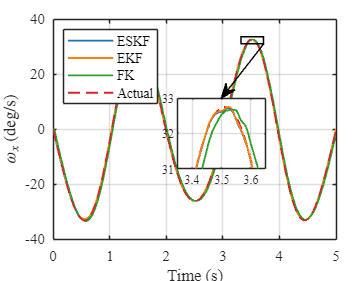

lineStyle1 = '-';  % ESKF Estimate
lineStyle2 = '-';  % EKF Estimate
lineStyle3 = '-';  % FK Estimate
lineStyle4 = '--'; % Actual / Ground Truth

lineWidth_main = 1.2;

% --- Create main plot ---
% fig_omega_x = figure('Name', 'X-Angular Velocity Tracking Comparison', 'Position', [100, 100, 600, 400], 'Color', 'w');
fig_omega_x = figure('Name', 'X-Angular Velocity Tracking Comparison', 'Position', fig_size, 'Color', 'w');
% Create main axes and save handle
% ax_main = axes('Position', [0.1, 0.12, 0.85, 0.8]);
ax_main = axes('Position', [0.15, 0.15, 0.80, 0.78]);
hold(ax_main, 'on');
plot(ax_main, t_gt, omega_x_eskf, 'Color', color1, 'LineStyle', lineStyle1, 'LineWidth', lineWidth_main, 'DisplayName', 'ESKF');
plot(ax_main, t_gt, omega_x_ekf,  'Color', color2, 'LineStyle', lineStyle2, 'LineWidth', lineWidth_main, 'DisplayName', 'EKF');
plot(ax_main, t_gt, omega_x_fk,   'Color', color3, 'LineStyle', lineStyle3, 'LineWidth', lineWidth_main, 'DisplayName', 'FK');
plot(ax_main, t_gt, omega_x_gt,   'Color', color4, 'LineStyle', lineStyle4, 'LineWidth', lineWidth_main, 'DisplayName', 'Actual');
hold(ax_main, 'off');
grid(ax_main, 'on'); box(ax_main, 'on');
xlabel(ax_main, 'Time (s)', 'FontSize', axisFontSize, 'FontName', fontName);
ylabel(ax_main, '$\omega_x$ (deg/s)', 'FontSize', axisFontSize, 'FontName', fontName, 'Interpreter', 'latex');
legend(ax_main, 'show', 'Location', 'northwest', 'FontSize', axisFontSize-1, 'FontName', fontName);
set(ax_main, 'FontSize', axisFontSize, 'FontName', fontName);
xlim(ax_main, [t_gt(1), t_gt(end)/4]);

% --- Define inset position (can be manually adjusted) ---
% Inset axes properties
inset_pos = [0.50, 0.40, 0.25, 0.25]; % inset axes position [left, bottom, width, height]

% --- Define the data range displayed in the inset (adjust as needed) ---
% These control the data range shown in the inset - adjust according to your data
zoom_xlim = [3.35, 3.65];          % X-axis range for zoomed region (data units)
zoom_ylim = [31, 33];              % Y-axis range for zoomed region (data units)

% --- Define black box properties (can be adjusted independently from inset) ---
% These directly control the black rectangle's position (independent from the inset)
box_x = 3.32;     % Left edge of the box
box_y = 31.2;     % Bottom edge of the box
box_w = 0.4;      % Width of the box
box_h = 2.5;      % Height of the box

% Draw the zoom box on the main plot
rectangle(ax_main, 'Position', [box_x, box_y, box_w, box_h], ...
          'EdgeColor', 'k', 'LineWidth', 1, 'LineStyle', '-');

% --- Create the inset axes for the zoomed region ---
ax_inset = axes('Position', inset_pos);
hold(ax_inset, 'on');
plot(ax_inset, t_gt, omega_x_gt,   'Color', color4, 'LineStyle', lineStyle4, 'LineWidth', lineWidth_main);
plot(ax_inset, t_gt, omega_x_eskf, 'Color', color1, 'LineStyle', lineStyle1, 'LineWidth', lineWidth_main);
plot(ax_inset, t_gt, omega_x_ekf,  'Color', color2, 'LineStyle', lineStyle2, 'LineWidth', lineWidth_main);
plot(ax_inset, t_gt, omega_x_fk,   'Color', color3, 'LineStyle', lineStyle3, 'LineWidth', lineWidth_main);
hold(ax_inset, 'off');
grid(ax_inset, 'on'); box(ax_inset, 'on');
xlim(ax_inset, zoom_xlim); % Use independently defined X range for the inset
ylim(ax_inset, zoom_ylim); % Use independently defined Y range for the inset
set(ax_inset, 'FontSize', axisFontSize-2, 'FontName', fontName);

% --- Add an arrow connecting the zoom box and the inset axes ---
% Convert the zoom box corner (in data units) to normalized figure units
main_ax_pos = get(ax_main, 'Position');
main_xlim = get(ax_main, 'XLim');
main_ylim = get(ax_main, 'YLim');

% Calculate normalized coordinates of the zoom box's lower right corner
x_norm_R = main_ax_pos(1) + main_ax_pos(3) * (box_x + box_w - main_xlim(1)) / diff(main_xlim);
y_norm_B = main_ax_pos(2) + main_ax_pos(4) * (box_y - main_ylim(1)) / diff(main_ylim);

% Middle top position of the inset axes (normalized units)
inset_norm_M = inset_pos(1) + inset_pos(3)/2;  % Center = left + half width
inset_norm_T = inset_pos(2) + inset_pos(4);    % Top edge

% Draw arrow from the lower right of the zoom box to the top middle of the inset
annotation(fig_omega_x, 'arrow', [x_norm_R, inset_norm_M], [y_norm_B, inset_norm_T], 'Color', 'k', 'LineWidth', 0.5);

%% Plot X-direction angular velocity error comparison

disp('Plotting X-direction angular velocity error comparison...');

Plotting X-direction angular velocity error comparison...



% --- Use existing data (avoid redundant calculation) ---
% If angular velocity errors have not been calculated, calculate them now
if ~exist('error_omega_x_eskf', 'var') || ~exist('error_omega_x_ekf', 'var') || ~exist('error_omega_x_fk', 'var')
    % Extract data
    t_gt = ground_truth_data.timestamps;
    omega_gt = ground_truth_data.angular_velocity;
    
    t_eskf = est_states_ESKF.timestamp;
    omega_eskf = est_states_ESKF.angular_velocity;
    
    t_ekf = est_states_EKF.timestamp;
    omega_ekf = est_states_EKF.angular_velocity;
    
    t_fk = est_states_FK.timestamp;
    omega_fk = est_states_FK.angular_velocity;
    
    % Interpolate to ground truth time axis
    omega_eskf_interp = interp1(t_eskf, omega_eskf, t_gt, 'linear', 'extrap');
    omega_ekf_interp = interp1(t_ekf, omega_ekf, t_gt, 'linear', 'extrap');
    omega_fk_interp = interp1(t_fk, omega_fk, t_gt, 'linear', 'extrap');
    
    % Extract X-direction angular velocity
    omega_x_gt = omega_gt(:, 1);
    omega_x_eskf = omega_eskf_interp(:, 1);
    omega_x_ekf = omega_ekf_interp(:, 1);
    omega_x_fk = omega_fk_interp(:, 1);
    
    % Calculate errors
    error_omega_x_eskf = omega_x_eskf - omega_x_gt;
    error_omega_x_ekf = omega_x_ekf - omega_x_gt;
    error_omega_x_fk = omega_x_fk - omega_x_gt;
end

%% Plot X-direction angular velocity error comparison (without RMSE labels)

disp('Plotting X-direction angular velocity error comparison...');

Plotting X-direction angular velocity error comparison...


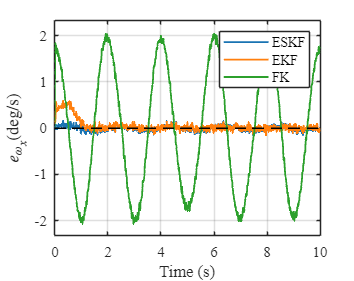


% --- Plotting parameters ---
lineStyle1 = '-';  % ESKF
lineStyle2 = '-';  % EKF
lineStyle3 = '-';  % FK
lineWidth_main = 1.2;

% --- Create figure ---
% fig_omega_x_error = figure('Name', 'X-Angular Velocity Error Comparison', 'Position', [100, 100, 600, 400], 'Color', 'w');
fig_omega_x_error = figure('Name', 'X-Angular Velocity Error Comparison', 'Position', fig_size, 'Color', 'w');
% --- Main plot ---
plot(t_gt, error_omega_x_eskf, 'Color', color1, 'LineStyle', lineStyle1, 'LineWidth', lineWidth_main, 'DisplayName', 'ESKF');
hold on;
plot(t_gt, error_omega_x_ekf, 'Color', color2, 'LineStyle', lineStyle2, 'LineWidth', lineWidth_main, 'DisplayName', 'EKF');
plot(t_gt, error_omega_x_fk, 'Color', color3, 'LineStyle', lineStyle3, 'LineWidth', lineWidth_main, 'DisplayName', 'FK');

% Add zero-error line
plot(t_gt([1, end]), [0, 0], 'k--', 'LineWidth', 1, 'DisplayName', '');

hold off;

% --- Set figure properties ---
grid on; box on;
xlabel('Time (s)', 'FontSize', axisFontSize, 'FontName', fontName);
ylabel('$e_{\omega_x}$(deg/s)', 'FontSize', axisFontSize, 'FontName', fontName, 'Interpreter', 'latex');

% Standard legend (without RMSE information)
legend('ESKF', 'EKF', 'FK', 'Location', 'northeast', 'FontSize', axisFontSize-1, 'FontName', fontName);

% Limit display range to the first half of the time
xlim([t_gt(1), t_gt(end)/2]);

% Set Y-axis range, slightly expanded to show all data
all_errors = [error_omega_x_eskf; error_omega_x_ekf; error_omega_x_fk];
error_range = max(abs(all_errors)) * 1.1;  % 10% larger than max error
ylim([-error_range, error_range]);

% Set font and size
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);

%% Plot acceleration RMSE comparison figure

disp('Plotting acceleration RMSE comparison figure...');

Plotting acceleration RMSE comparison figure...


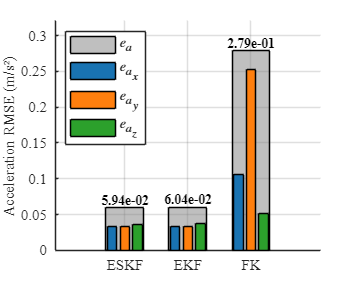


% --- Extract acceleration data ---
t_gt = ground_truth_data.timestamps;
accel_gt = ground_truth_data.acceleration;

t_eskf = est_states_ESKF.timestamp;
accel_eskf = est_states_ESKF.acceleration;

t_ekf = est_states_EKF.timestamp;
accel_ekf = est_states_EKF.acceleration;

t_fk = est_states_FK.timestamp;
accel_fk = est_states_FK.acceleration;

% --- Ensure all data is on the same time axis (interpolate to the ground truth time axis) ---
accel_eskf_interp = interp1(t_eskf, accel_eskf, t_gt, 'linear', 'extrap');
accel_ekf_interp = interp1(t_ekf, accel_ekf, t_gt, 'linear', 'extrap');
accel_fk_interp = interp1(t_fk, accel_fk, t_gt, 'linear', 'extrap');

% --- Extract XYZ components of acceleration ---
% X-direction acceleration
accel_x_gt = accel_gt(:, 1);
accel_x_eskf = accel_eskf_interp(:, 1);
accel_x_ekf = accel_ekf_interp(:, 1);
accel_x_fk = accel_fk_interp(:, 1);

% Y-direction acceleration
accel_y_gt = accel_gt(:, 2);
accel_y_eskf = accel_eskf_interp(:, 2);
accel_y_ekf = accel_ekf_interp(:, 2);
accel_y_fk = accel_fk_interp(:, 2);

% Z-direction acceleration
accel_z_gt = accel_gt(:, 3);
accel_z_eskf = accel_eskf_interp(:, 3);
accel_z_ekf = accel_ekf_interp(:, 3);
accel_z_fk = accel_fk_interp(:, 3);

% --- Calculate acceleration errors ---
% X acceleration error
error_accel_x_eskf = accel_x_eskf - accel_x_gt;
error_accel_x_ekf = accel_x_ekf - accel_x_gt;
error_accel_x_fk = accel_x_fk - accel_x_gt;

% Y acceleration error
error_accel_y_eskf = accel_y_eskf - accel_y_gt;
error_accel_y_ekf = accel_y_ekf - accel_y_gt;
error_accel_y_fk = accel_y_fk - accel_y_gt;

% Z acceleration error
error_accel_z_eskf = accel_z_eskf - accel_z_gt;
error_accel_z_ekf = accel_z_ekf - accel_z_gt;
error_accel_z_fk = accel_z_fk - accel_z_gt;

% --- Calculate RMSE ---
% ESKF acceleration RMSE
eskf_accel_x_rmse = sqrt(mean(error_accel_x_eskf.^2));
eskf_accel_y_rmse = sqrt(mean(error_accel_y_eskf.^2));
eskf_accel_z_rmse = sqrt(mean(error_accel_z_eskf.^2));
eskf_accel_rmse_xyz = [eskf_accel_x_rmse, eskf_accel_y_rmse, eskf_accel_z_rmse];
% Calculate overall acceleration RMSE
eskf_accel_rmse = sqrt(mean(error_accel_x_eskf.^2 + error_accel_y_eskf.^2 + error_accel_z_eskf.^2));

% EKF acceleration RMSE
ekf_accel_x_rmse = sqrt(mean(error_accel_x_ekf.^2));
ekf_accel_y_rmse = sqrt(mean(error_accel_y_ekf.^2));
ekf_accel_z_rmse = sqrt(mean(error_accel_z_ekf.^2));
ekf_accel_rmse_xyz = [ekf_accel_x_rmse, ekf_accel_y_rmse, ekf_accel_z_rmse];
% Calculate overall acceleration RMSE
ekf_accel_rmse = sqrt(mean(error_accel_x_ekf.^2 + error_accel_y_ekf.^2 + error_accel_z_ekf.^2));

% FK acceleration RMSE
fk_accel_x_rmse = sqrt(mean(error_accel_x_fk.^2));
fk_accel_y_rmse = sqrt(mean(error_accel_y_fk.^2));
fk_accel_z_rmse = sqrt(mean(error_accel_z_fk.^2));
fk_accel_rmse_xyz = [fk_accel_x_rmse, fk_accel_y_rmse, fk_accel_z_rmse];
% Calculate overall acceleration RMSE
fk_accel_rmse = sqrt(mean(error_accel_x_fk.^2 + error_accel_y_fk.^2 + error_accel_z_fk.^2));

% --- Plot acceleration RMSE comparison ---
% Set plotting parameters
algorithms = {'ESKF', 'EKF', 'FK'};
x_indices = 1:length(algorithms);
bar_width_overall = 0.6;
bar_width_detail = 0.15;
group_offset = 0.2;

% Create figure
% fig_accel_rmse = figure('Name', 'Linear Acceleration RMSE Comparison', 'Position', [100, 100, 550, 450], 'Color', 'w');
fig_accel_rmse = figure('Name', 'Linear Acceleration RMSE Comparison', 'Position', fig_size, 'Color', 'w');
hold on;

accel_rmse_overall = [eskf_accel_rmse, ekf_accel_rmse, fk_accel_rmse];
accel_rmse_xyz = [eskf_accel_rmse_xyz; ekf_accel_rmse_xyz; fk_accel_rmse_xyz]'; % 3xN

% Plot overall RMSE bars
b_accel_overall = bar(x_indices, accel_rmse_overall, bar_width_overall, 'FaceColor', [0.5, 0.5, 0.5], 'FaceAlpha', 0.5, 'EdgeColor','k');

% Plot XYZ component bars
b_x = bar(x_indices - group_offset, accel_rmse_xyz(1,:), bar_width_detail, 'FaceColor', color1);
b_y = bar(x_indices,                accel_rmse_xyz(2,:), bar_width_detail, 'FaceColor', color2);
b_z = bar(x_indices + group_offset, accel_rmse_xyz(3,:), bar_width_detail, 'FaceColor', color3);

hold off;

set(gca, 'XTick', x_indices, 'XTickLabel', algorithms, 'FontSize', axisFontSize, 'FontName', fontName);
ylabel('Acceleration RMSE (m/s²)', 'FontSize', plotFontSize, 'FontName', fontName);
grid on;
legend([b_accel_overall, b_x, b_y, b_z], {'$e_{a}$', '$e_{a_x}$', '$e_{a_y}$', '$e_{a_z}$'}, ...
    'Location', 'northwest', 'FontSize', plotFontSize-1, 'FontName', fontName, 'Interpreter', 'latex');
ylim([0, max([accel_rmse_overall, accel_rmse_xyz(:)']) * 1.15]);

% Add value labels to the overall RMSE bars (using scientific notation)
for j = 1:length(accel_rmse_overall)
    text(x_indices(j), accel_rmse_overall(j), sprintf('%.2e', accel_rmse_overall(j)), ...
         'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', ...
         'FontSize', axisFontSize - 1, 'FontName', fontName, 'Color', 'k', 'FontWeight', 'bold');
end

%% Plot X-direction acceleration tracking with adjustable local zoomed-in inset

disp('Plotting X-direction acceleration tracking curve (with adjustable local zoom)...');

Plotting X-direction acceleration tracking curve (with adjustable local zoom)...


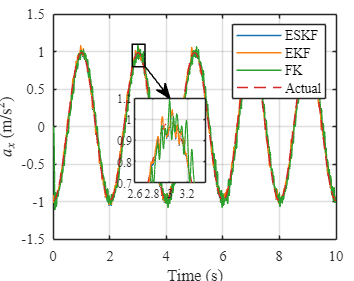

lineStyle1 = '-';  % ESKF Estimate
lineStyle2 = '-';  % EKF Estimate
lineStyle3 = '-';  % FK Estimate
lineStyle4 = '--'; % Actual/Ground Truth

lineWidth_main = 1.0;
lineWidth_inner = 0.8;

% --- Create main plot ---
% fig_accel_x = figure('Name', 'X-Linear Acceleration Tracking Comparison', 'Position', [100, 100, 600, 400], 'Color', 'w');
fig_accel_x = figure('Name', 'X-Linear Acceleration Tracking Comparison', 'Position', fig_size, 'Color', 'w');
% Create main axes and save handle
ax_main = axes('Position', [0.15, 0.15, 0.8, 0.8]);
hold(ax_main, 'on');
plot(ax_main, t_gt, accel_x_eskf, 'Color', color1, 'LineStyle', lineStyle1, 'LineWidth', lineWidth_main, 'DisplayName', 'ESKF');
plot(ax_main, t_gt, accel_x_ekf,  'Color', color2, 'LineStyle', lineStyle2, 'LineWidth', lineWidth_main, 'DisplayName', 'EKF');
plot(ax_main, t_gt, accel_x_fk,   'Color', color3, 'LineStyle', lineStyle3, 'LineWidth', lineWidth_main, 'DisplayName', 'FK');
plot(ax_main, t_gt, accel_x_gt,   'Color', color4, 'LineStyle', lineStyle4, 'LineWidth', lineWidth_main, 'DisplayName', 'Actual');
hold(ax_main, 'off');
grid(ax_main, 'on'); box(ax_main, 'on');
xlabel(ax_main, 'Time (s)', 'FontSize', axisFontSize, 'FontName', fontName);
ylabel(ax_main, '$a_x$ (m/s$^2$)', 'FontSize', axisFontSize, 'FontName', fontName, 'Interpreter', 'latex');
legend(ax_main, 'show', 'Location', 'northeast', 'FontSize', axisFontSize-1, 'FontName', fontName);
set(ax_main, 'FontSize', axisFontSize, 'FontName', fontName);
xlim(ax_main, [t_gt(1), t_gt(end)/2]);

% --- Define inset position (can be adjusted manually) ---
% Inset axes properties
inset_pos = [0.38, 0.350, 0.20, 0.30]; % inset axes position [left, bottom, width, height]

% --- Define the data range displayed in the inset (can be adjusted manually) ---
% These control the data range shown in the inset - adjust according to your data
zoom_xlim = [2.6, 3.4];           % X-axis range for zoomed region (data units)
zoom_ylim = [0.7, 1.1];           % Y-axis range for zoomed region (data units)

% --- Define black box properties (can be adjusted independently from the inset) ---
% These directly control the black rectangle's position (independent from the inset)
box_x = 2.8;     % Left edge of the box
box_y = 0.8;     % Bottom edge of the box
box_w = 0.45;    % Width of the box
box_h = 0.3;     % Height of the box

% Draw the zoom box on the main plot
rectangle(ax_main, 'Position', [box_x, box_y, box_w, box_h], ...
          'EdgeColor', 'k', 'LineWidth', 1, 'LineStyle', '-');

% --- Create the inset axes for the zoomed region ---
ax_inset = axes('Position', inset_pos);
hold(ax_inset, 'on');
plot(ax_inset, t_gt, accel_x_gt,   'Color', color4, 'LineStyle', lineStyle4, 'LineWidth', lineWidth_inner);
plot(ax_inset, t_gt, accel_x_eskf, 'Color', color1, 'LineStyle', lineStyle1, 'LineWidth', lineWidth_inner);
plot(ax_inset, t_gt, accel_x_ekf,  'Color', color2, 'LineStyle', lineStyle2, 'LineWidth', lineWidth_inner);
plot(ax_inset, t_gt, accel_x_fk,   'Color', color3, 'LineStyle', lineStyle3, 'LineWidth', lineWidth_inner);
hold(ax_inset, 'off');
grid(ax_inset, 'on'); box(ax_inset, 'on');
xlim(ax_inset, zoom_xlim); % Use independently defined X range for the inset
ylim(ax_inset, zoom_ylim); % Use independently defined Y range for the inset
set(ax_inset, 'FontSize', axisFontSize-2, 'FontName', fontName);

% --- Add an arrow connecting the zoom box and the inset axes ---
% Convert the zoom box corner (in data units) to normalized figure units
main_ax_pos = get(ax_main, 'Position');
main_xlim = get(ax_main, 'XLim');
main_ylim = get(ax_main, 'YLim');

% Calculate normalized coordinates of the zoom box's lower right corner
x_norm_R = main_ax_pos(1) + main_ax_pos(3) * (box_x + box_w - main_xlim(1)) / diff(main_xlim);
y_norm_B = main_ax_pos(2) + main_ax_pos(4) * (box_y - main_ylim(1)) / diff(main_ylim);

% Middle top position of the inset axes (normalized units)
inset_norm_M = inset_pos(1) + inset_pos(3)/2;  % Center = left + half width
inset_norm_T = inset_pos(2) + inset_pos(4);    % Top edge

% Draw arrow from the lower right of the zoom box to the top middle of the inset
annotation(fig_accel_x, 'arrow', [x_norm_R, inset_norm_M], [y_norm_B, inset_norm_T], 'Color', 'k', 'LineWidth', 0.5);

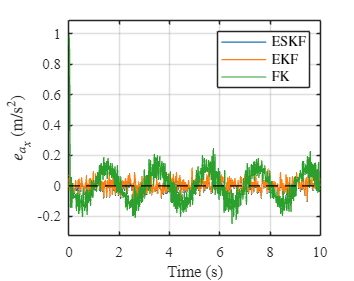

% --- Plot combined X-acceleration error curves for all three filters ---
% fig_combined = figure('Name', 'Combined X-Acceleration Errors', 'Position', [700, 300, 800, 500], 'Color', 'w');
fig_combined = figure('Name', 'Combined X-Acceleration Errors', 'Position', fig_size, 'Color', 'w');
hold on;

% Define line styles and colors (inferred from reference code)
lineStyle1 = '-';
lineStyle2 = '-';
lineStyle3 = '-';
linewidth_acc = 0.8;
% Plot error curves for all three filters
plot(t_gt, error_accel_x_eskf, 'Color', color1, 'LineStyle', lineStyle1, 'LineWidth', linewidth_acc, 'DisplayName', 'ESKF');
plot(t_gt, error_accel_x_ekf, 'Color', color2, 'LineStyle', lineStyle2, 'LineWidth', linewidth_acc, 'DisplayName', 'EKF');
plot(t_gt, error_accel_x_fk, 'Color', color3, 'LineStyle', lineStyle3, 'LineWidth', linewidth_acc, 'DisplayName', 'FK');

% Zero error line
plot(t_gt, zeros(size(t_gt)), 'k--', 'LineWidth', 0.5, 'HandleVisibility', 'off');

hold off;
grid on; box on;
xlabel('Time (s)', 'FontSize', axisFontSize, 'FontName', fontName);
ylabel('$e_{a_x}$ (m/s$^2$)', 'FontSize', axisFontSize, 'FontName', fontName, 'Interpreter', 'latex');

% Use LaTeX interpreter to ensure correct symbol display
legend('show', 'Location', 'northeast', 'FontSize', axisFontSize-1, 'FontName', fontName, 'Interpreter', 'latex', 'NumColumns', 1);

set(gca, 'FontSize', axisFontSize, 'FontName', fontName);

% Calculate appropriate y-axis range
all_errors = [error_accel_x_eskf; error_accel_x_ekf; error_accel_x_fk];
          
ylim_val = max(abs(all_errors)) * 1.1;
ylim([-ylim_val * 0.3, ylim_val]);
xlim([t_gt(1), t_gt(end)/2]);

%% Plot Y-direction acceleration tracking with adjustable local zoomed-in inset
lineWidth_y_ac = 1.2;
disp('Plotting Y-direction acceleration tracking curve (with adjustable local zoom)...');

Plotting Y-direction acceleration tracking curve (with adjustable local zoom)...


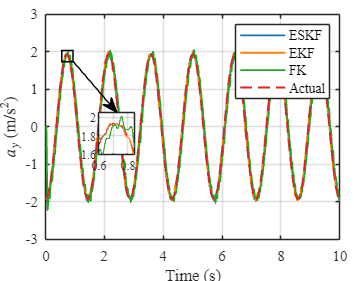

% Line styles and colors follow previous code
% fig_accel_y = figure('Name', 'Y-Linear Acceleration Tracking Comparison', 'Position', [100, 100, 600, 400], 'Color', 'w');
fig_accel_y = figure('Name', 'Y-Linear Acceleration Tracking Comparison', 'Position', fig_size, 'Color', 'w');
ax_main_y = axes('Position', [0.13, 0.15, 0.83, 0.8]);
hold(ax_main_y, 'on');
plot(ax_main_y, t_gt, accel_y_eskf, 'Color', color1, 'LineStyle', lineStyle1, 'LineWidth', lineWidth_y_ac, 'DisplayName', 'ESKF');
plot(ax_main_y, t_gt, accel_y_ekf,  'Color', color2, 'LineStyle', lineStyle2, 'LineWidth', lineWidth_y_ac, 'DisplayName', 'EKF');
plot(ax_main_y, t_gt, accel_y_fk,   'Color', color3, 'LineStyle', lineStyle3, 'LineWidth', lineWidth_y_ac, 'DisplayName', 'FK');
plot(ax_main_y, t_gt, accel_y_gt,   'Color', color4, 'LineStyle', lineStyle4, 'LineWidth', lineWidth_y_ac, 'DisplayName', 'Actual');
hold(ax_main_y, 'off');
grid(ax_main_y, 'on'); box(ax_main_y, 'on');
xlabel(ax_main_y, 'Time (s)', 'FontSize', axisFontSize, 'FontName', fontName);
ylabel(ax_main_y, '$a_y$ (m/s$^2$)', 'FontSize', axisFontSize, 'FontName', fontName, 'Interpreter', 'latex');
legend(ax_main_y, 'show', 'Location', 'northeast', 'FontSize', axisFontSize-1, 'FontName', fontName);
set(ax_main_y, 'FontSize', axisFontSize, 'FontName', fontName);
xlim(ax_main_y, [t_gt(1), t_gt(end)/2]);

% Inset parameters can be adjusted according to data
inset_pos_y = [0.28, 0.450, 0.10, 0.15];
zoom_xlim_y = [0.6, 0.85];
zoom_ylim_y = [1.6, 2.05];

box_x_y = 0.55;
box_y_y = 1.73;
box_w_y = 0.38;
box_h_y = 0.3;

rectangle(ax_main_y, 'Position', [box_x_y, box_y_y, box_w_y, box_h_y], ...
          'EdgeColor', 'k', 'LineWidth', 1, 'LineStyle', '-');

ax_inset_y = axes('Position', inset_pos_y);
hold(ax_inset_y, 'on');
plot(ax_inset_y, t_gt, accel_y_gt,   'Color', color4, 'LineStyle', lineStyle4, 'LineWidth', lineWidth_inner);
plot(ax_inset_y, t_gt, accel_y_eskf, 'Color', color1, 'LineStyle', lineStyle1, 'LineWidth', lineWidth_inner);
plot(ax_inset_y, t_gt, accel_y_ekf,  'Color', color2, 'LineStyle', lineStyle2, 'LineWidth', lineWidth_inner);
plot(ax_inset_y, t_gt, accel_y_fk,   'Color', color3, 'LineStyle', lineStyle3, 'LineWidth', lineWidth_inner);
hold(ax_inset_y, 'off');
grid(ax_inset_y, 'on'); box(ax_inset_y, 'on');
xlim(ax_inset_y, zoom_xlim_y);
ylim(ax_inset_y, zoom_ylim_y);
set(ax_inset_y, 'FontSize', axisFontSize-2, 'FontName', fontName);

% Arrow
main_ax_pos_y = get(ax_main_y, 'Position');
main_xlim_y = get(ax_main_y, 'XLim');
main_ylim_y = get(ax_main_y, 'YLim');
x_norm_R_y = main_ax_pos_y(1) + main_ax_pos_y(3) * (box_x_y + box_w_y - main_xlim_y(1)) / diff(main_xlim_y);
y_norm_B_y = main_ax_pos_y(2) + main_ax_pos_y(4) * (box_y_y - main_ylim_y(1)) / diff(main_ylim_y);
inset_norm_M_y = inset_pos_y(1) + inset_pos_y(3)/2;
inset_norm_T_y = inset_pos_y(2) + inset_pos_y(4);
annotation(fig_accel_y, 'arrow', [x_norm_R_y, inset_norm_M_y], [y_norm_B_y, inset_norm_T_y], 'Color', 'k', 'LineWidth', 0.5);

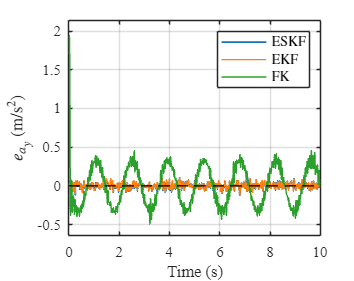

%% Plot combined Y-acceleration error curves for all three filters
% fig_combined_y = figure('Name', 'Combined Y-Acceleration Errors', 'Position', [700, 300, 800, 500], 'Color', 'w');
fig_combined_y = figure('Name', 'Combined Y-Acceleration Errors', 'Position', fig_size, 'Color', 'w');
hold on;
plot(t_gt, error_accel_y_eskf, 'Color', color1, 'LineStyle', lineStyle1, 'LineWidth', 1.1, 'DisplayName', 'ESKF');
plot(t_gt, error_accel_y_ekf, 'Color', color2, 'LineStyle', lineStyle2, 'LineWidth', 0.9, 'DisplayName', 'EKF');
plot(t_gt, error_accel_y_fk,  'Color', color3, 'LineStyle', lineStyle3, 'LineWidth', 1.0, 'DisplayName', 'FK');
plot(t_gt, zeros(size(t_gt)), 'k--', 'LineWidth', 0.5, 'HandleVisibility', 'off');
hold off;
grid on; box on;
xlabel('Time (s)', 'FontSize', axisFontSize, 'FontName', fontName);
ylabel('$e_{a_y}$ (m/s$^2$)', 'FontSize', axisFontSize, 'FontName', fontName, 'Interpreter', 'latex');
legend('show', 'Location', 'northeast', 'FontSize', axisFontSize-1, 'FontName', fontName, 'Interpreter', 'latex', 'NumColumns', 1);
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);
all_errors_y = [error_accel_y_eskf; error_accel_y_ekf; error_accel_y_fk];
ylim_val_y = max(abs(all_errors_y)) * 1.1;
ylim([-ylim_val_y * 0.3, ylim_val_y]);
xlim([t_gt(1), t_gt(end)/2]);

% loading true bias
load('true_bias_values.mat');

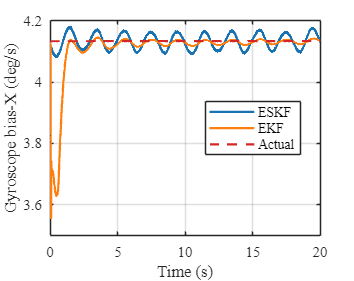

% Gyroscope bias X estimation
% fig1 = figure('Position', [100, 100, 550, 450], 'Color', 'w');
fig1 = figure('Position', fig_size, 'Color', 'w');
plot(t_gt, rad2deg(est_states_ESKF.gyro_bias(:, 1)), '-', 'LineWidth', 1.5, 'Color', color1, 'DisplayName', 'ESKF');
hold on;
plot(t_gt, rad2deg(est_states_EKF.gyro_bias(:, 1)), '-', 'LineWidth', 1.5, 'Color', color2, 'DisplayName', 'EKF');
plot(t_gt, true_biases.gyro_bias(:, 1), '--', 'LineWidth', 1.5, 'Color', color4, 'DisplayName', 'Actual');
hold off;
xlabel('Time (s)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Gyroscope bias-X (deg/s)', 'FontSize', plotFontSize, 'FontName', fontName);
legend('show', 'Location', 'best', 'FontSize', plotFontSize-1, 'FontName', fontName);
grid on;
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);

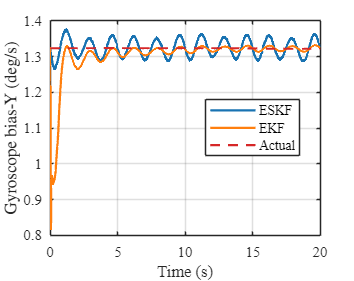

% Gyroscope bias Y estimation
% fig2 = figure('Position', [100, 100, 550, 450], 'Color', 'w');
fig2 = figure('Position', fig_size, 'Color', 'w');
plot(t_gt, rad2deg(est_states_ESKF.gyro_bias(:, 2)), '-', 'LineWidth', 1.5, 'Color', color1, 'DisplayName', 'ESKF');
hold on;
plot(t_gt, rad2deg(est_states_EKF.gyro_bias(:, 2)), '-', 'LineWidth', 1.5, 'Color', color2, 'DisplayName', 'EKF');
plot(t_gt, true_biases.gyro_bias(:, 2), '--', 'LineWidth', 1.5, 'Color', color4, 'DisplayName', 'Actual');
hold off;
xlabel('Time (s)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Gyroscope bias-Y (deg/s)', 'FontSize', plotFontSize, 'FontName', fontName, 'Interpreter', 'latex');
legend('show', 'Location', 'best', 'FontSize', plotFontSize-1, 'FontName', fontName);
grid on;
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);

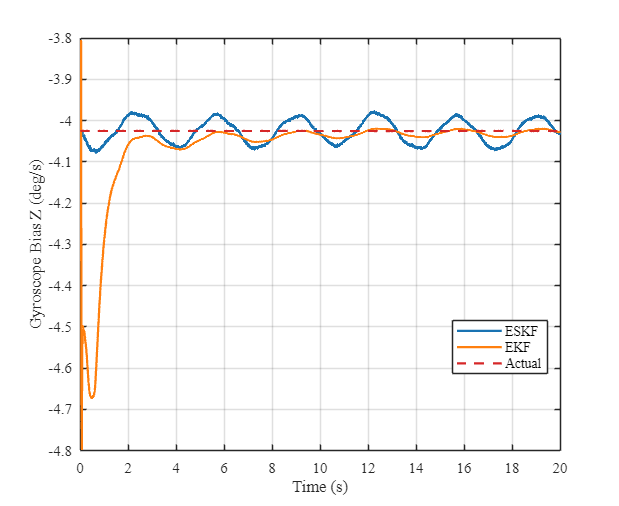

% Gyroscope bias Z estimation
fig3 = figure('Position', [100, 100, 550, 450], 'Color', 'w');
plot(t_gt, rad2deg(est_states_ESKF.gyro_bias(:, 3)), '-', 'LineWidth', 1.5, 'Color', color1, 'DisplayName', 'ESKF');
hold on;
plot(t_gt, rad2deg(est_states_EKF.gyro_bias(:, 3)), '-', 'LineWidth', 1.5, 'Color', color2, 'DisplayName', 'EKF');
plot(t_gt, true_biases.gyro_bias(:, 3), '--', 'LineWidth', 1.5, 'Color', color4, 'DisplayName', 'Actual');
hold off;
xlabel('Time (s)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Gyroscope Bias Z (deg/s)', 'FontSize', plotFontSize, 'FontName', fontName);
legend('show', 'Location', 'best', 'FontSize', plotFontSize-1, 'FontName', fontName);
grid on;
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);

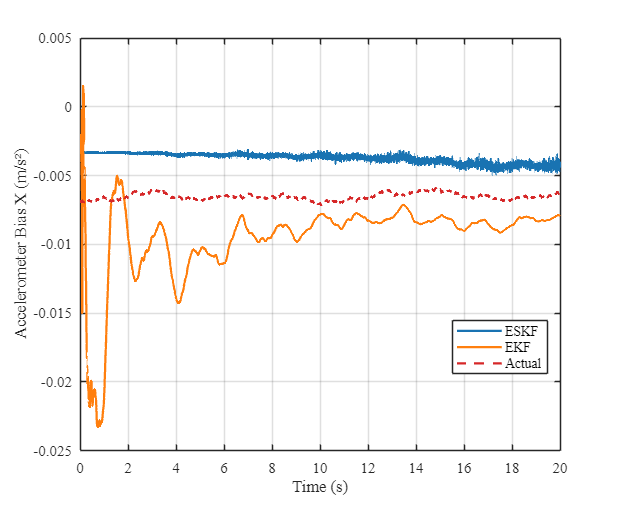

% Accelerometer bias X estimation
fig4 = figure('Position', [100, 100, 550, 450], 'Color', 'w');
plot(t_gt, est_states_ESKF.acce_bias(:, 1), '-', 'LineWidth', 1.5, 'Color', color1, 'DisplayName', 'ESKF');
hold on;
plot(t_gt, est_states_EKF.acce_bias(:, 1), '-', 'LineWidth', 1.5, 'Color', color2, 'DisplayName', 'EKF');
plot(t_gt, true_biases.acce_bias(:, 1), '--', 'LineWidth', 1.5, 'Color', color4, 'DisplayName', 'Actual');
hold off;
xlabel('Time (s)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Accelerometer Bias X (m/s²)', 'FontSize', plotFontSize, 'FontName', fontName);
legend('show', 'Location', 'best', 'FontSize', plotFontSize-1, 'FontName', fontName);
grid on;
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);

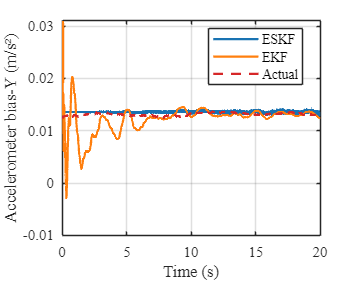

% Accelerometer bias Y estimation
% fig5 = figure('Position', [100, 100, 550, 450], 'Color', 'w');
fig5 = figure('Position', fig_size, 'Color', 'w');
plot(t_gt, est_states_ESKF.acce_bias(:, 2), '-', 'LineWidth', 1.5, 'Color', color1, 'DisplayName', 'ESKF');
hold on;
plot(t_gt, est_states_EKF.acce_bias(:, 2), '-', 'LineWidth', 1.5, 'Color', color2, 'DisplayName', 'EKF');
plot(t_gt, true_biases.acce_bias(:, 2), '--', 'LineWidth', 1.5, 'Color', color4, 'DisplayName', 'Actual');
hold off;
xlabel('Time (s)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Accelerometer bias-Y (m/s²)', 'FontSize', plotFontSize, 'FontName', fontName);
legend('show', 'Location', 'best', 'FontSize', plotFontSize-1, 'FontName', fontName);
grid on;
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);

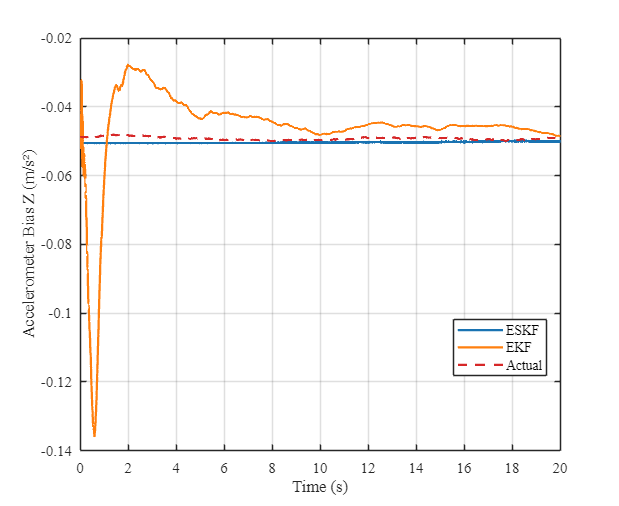

% Accelerometer bias Z estimation
fig6 = figure('Position', [100, 100, 550, 450], 'Color', 'w');
plot(t_gt, est_states_ESKF.acce_bias(:, 3), '-', 'LineWidth', 1.5, 'Color', color1, 'DisplayName', 'ESKF');
hold on;
plot(t_gt, est_states_EKF.acce_bias(:, 3), '-', 'LineWidth', 1.5, 'Color', color2, 'DisplayName', 'EKF');
plot(t_gt, true_biases.acce_bias(:, 3), '--', 'LineWidth', 1.5, 'Color', color4, 'DisplayName', 'Actual');
hold off;
xlabel('Time (s)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Accelerometer Bias Z (m/s²)', 'FontSize', plotFontSize, 'FontName', fontName);
legend('show', 'Location', 'best', 'FontSize', plotFontSize-1, 'FontName', fontName);
grid on;
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);

% Calculating Error
error_roll_eskf = euler_eskf_interp(:, 1) - euler_gt(:, 1);
error_roll_ekf = euler_ekf_interp(:, 1) - euler_gt(:, 1);
error_roll_fk = euler_fk_interp(:, 1) - euler_gt(:, 1);

% Calculating Error
error_pitch_eskf = euler_eskf_interp(:, 2) - euler_gt(:, 2);
error_pitch_ekf = euler_ekf_interp(:, 2) - euler_gt(:, 2);
error_pitch_fk = euler_fk_interp(:, 2) - euler_gt(:, 2);

% Calculating Error
error_yaw_eskf = euler_eskf_interp(:, 3) - euler_gt(:, 3);
error_yaw_ekf = euler_ekf_interp(:, 3) - euler_gt(:, 3);
error_yaw_fk = euler_fk_interp(:, 3) - euler_gt(:, 3);

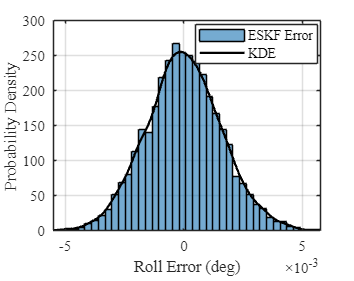

% 1. ESKF error probability distribution histogram (Roll error)
% fig1 = figure('Position', [100, 100, 550, 450], 'Color', 'w');
fig1 = figure('Position', fig_size, 'Color', 'w');
histogram(error_roll_eskf, 'Normalization', 'pdf', 'NumBins', 40, 'DisplayName', 'ESKF Error', 'FaceColor', color1);
hold on;
[f_eskf, xi_eskf] = ksdensity(error_roll_eskf);
plot(xi_eskf, f_eskf, 'k-', 'LineWidth', 1.5, 'DisplayName', 'KDE');
hold off;
xlabel('Roll Error (deg)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Probability Density', 'FontSize', plotFontSize, 'FontName', fontName);
% title('Roll Angle Error Distribution (ESKF)', 'FontSize', plotFontSize+1, 'FontName', fontName);
legend('show', 'Location', 'northeast', 'FontSize', plotFontSize-1, 'FontName', fontName);
grid on;
xlim([min(error_roll_eskf) max(error_roll_eskf)]);
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);
legend("Position", [0.55138,0.77299,0.34567,0.138])

% legend("Position", [0.55501,0.777,0.33932,0.138])

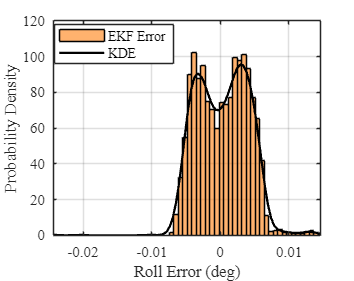

% 2. EKF error probability distribution histogram (Roll error)
% fig2 = figure('Position', [100, 100, 550, 450], 'Color', 'w');
fig2 = figure('Position', fig_size, 'Color', 'w');
histogram(error_roll_ekf, 'Normalization', 'pdf', 'NumBins', 60, 'DisplayName', 'EKF Error', 'FaceColor', color2);
hold on;
[f_ekf, xi_ekf] = ksdensity(error_roll_ekf);
plot(xi_ekf, f_ekf, 'k-', 'LineWidth', 1.5, 'DisplayName', 'KDE');
hold off;
xlabel('Roll Error (deg)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Probability Density', 'FontSize', plotFontSize, 'FontName', fontName);
% title('Roll Angle Error Distribution (EKF)', 'FontSize', plotFontSize+1, 'FontName', fontName);
legend('show', 'Location', 'northeast', 'FontSize', plotFontSize-1, 'FontName', fontName);
grid on;
xlim([min(error_roll_ekf)*1 max(error_roll_ekf)*1]);
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);
legend("Position", [0.16064,0.77432,0.32347,0.138])

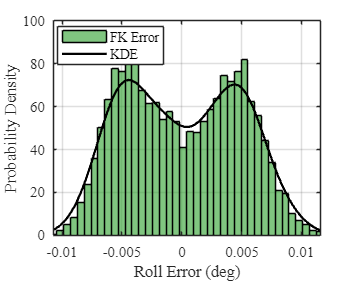

% 3. FK error probability distribution histogram (Roll error)
% fig3 = figure('Position', [100, 100, 550, 450], 'Color', 'w');
fig3 = figure('Position', fig_size, 'Color', 'w');
histogram(error_roll_fk, 'Normalization', 'pdf', 'NumBins', 40, 'DisplayName', 'FK Error', 'FaceColor', color3);
hold on;
[f_fk, xi_fk] = ksdensity(error_roll_fk);
plot(xi_fk, f_fk, 'k-', 'LineWidth', 1.5, 'DisplayName', 'KDE');
hold off;
xlabel('Roll Error (deg)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Probability Density', 'FontSize', plotFontSize, 'FontName', fontName);
% title('Roll Angle Error Distribution (FK)', 'FontSize', plotFontSize+1, 'FontName', fontName);
legend('show', 'Location', 'northeast', 'FontSize', plotFontSize-1, 'FontName', fontName);
grid on;
xlim([min(error_roll_fk) max(error_roll_fk)]);
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);
legend("Position", [0.16192,0.76966,0.30127,0.138])

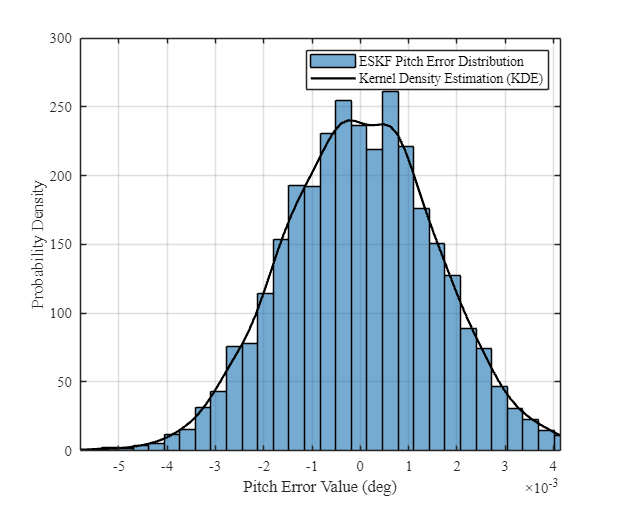

% 4. ESKF error probability distribution histogram (Pitch error)
fig4 = figure('Position', [100, 100, 550, 450], 'Color', 'w');
histogram(error_pitch_eskf, 'Normalization', 'pdf', 'NumBins', 40, 'DisplayName', 'ESKF Pitch Error Distribution', 'FaceColor', color1);
hold on;
[f_eskf, xi_eskf] = ksdensity(error_pitch_eskf);
plot(xi_eskf, f_eskf, 'k-', 'LineWidth', 1.5, 'DisplayName', 'Kernel Density Estimation (KDE)');
hold off;
xlabel('Pitch Error Value (deg)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Probability Density', 'FontSize', plotFontSize, 'FontName', fontName);
% title('Pitch Angle Error Distribution (ESKF)', 'FontSize', plotFontSize+1, 'FontName', fontName);
legend('show', 'Location', 'northeast', 'FontSize', plotFontSize-1, 'FontName', fontName);
grid on;
xlim([min(error_pitch_eskf) max(error_pitch_eskf)*0.6]);
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);

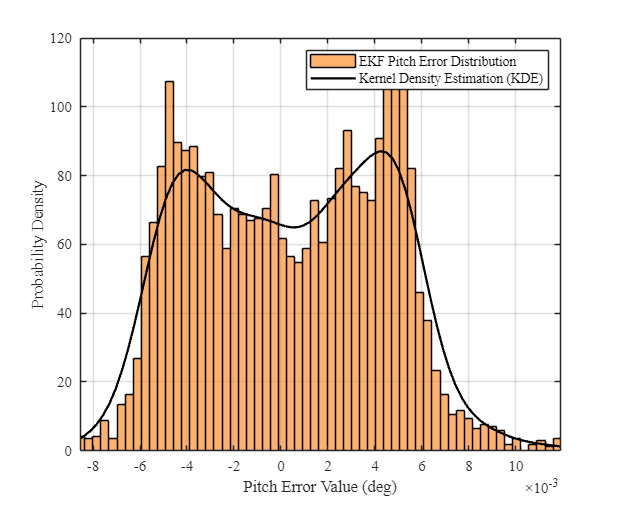

% 5. EKF error probability distribution histogram (Pitch error)
fig5 = figure('Position', [100, 100, 550, 450], 'Color', 'w');
histogram(error_pitch_ekf, 'Normalization', 'pdf', 'NumBins', 60, 'DisplayName', 'EKF Pitch Error Distribution', 'FaceColor', color2);
hold on;
[f_ekf, xi_ekf] = ksdensity(error_pitch_ekf);
plot(xi_ekf, f_ekf, 'k-', 'LineWidth', 1.5, 'DisplayName', 'Kernel Density Estimation (KDE)');
hold off;
xlabel('Pitch Error Value (deg)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Probability Density', 'FontSize', plotFontSize, 'FontName', fontName);
% title('Pitch Angle Error Distribution (EKF)', 'FontSize', plotFontSize+1, 'FontName', fontName);
legend('show', 'Location', 'northeast', 'FontSize', plotFontSize-1, 'FontName', fontName);
grid on;
xlim([min(error_pitch_ekf) max(error_pitch_ekf)]);
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);

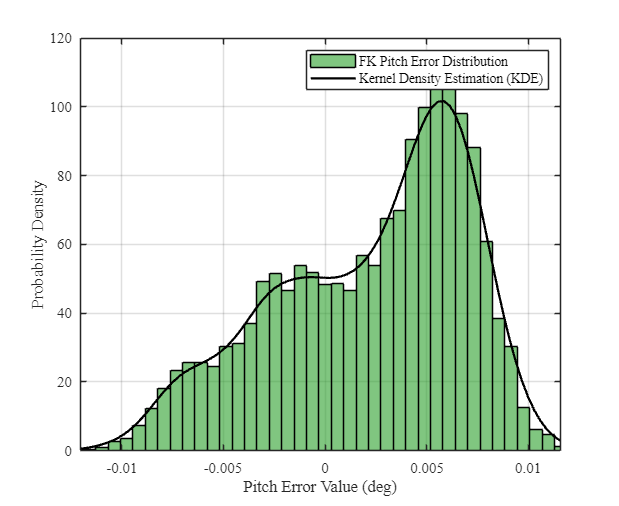

% 6. FK error probability distribution histogram (Pitch error)
fig6 = figure('Position', [100, 100, 550, 450], 'Color', 'w');
histogram(error_pitch_fk, 'Normalization', 'pdf', 'NumBins', 40, 'DisplayName', 'FK Pitch Error Distribution', 'FaceColor', color3);
hold on;
[f_fk, xi_fk] = ksdensity(error_pitch_fk);
plot(xi_fk, f_fk, 'k-', 'LineWidth', 1.5, 'DisplayName', 'Kernel Density Estimation (KDE)');
hold off;
xlabel('Pitch Error Value (deg)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Probability Density', 'FontSize', plotFontSize, 'FontName', fontName);
% title('Pitch Angle Error Distribution (FK)', 'FontSize', plotFontSize+1, 'FontName', fontName);
legend('show', 'Location', 'northeast', 'FontSize', plotFontSize-1, 'FontName', fontName);
grid on;
xlim([min(error_pitch_fk) max(error_pitch_fk)]);
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);

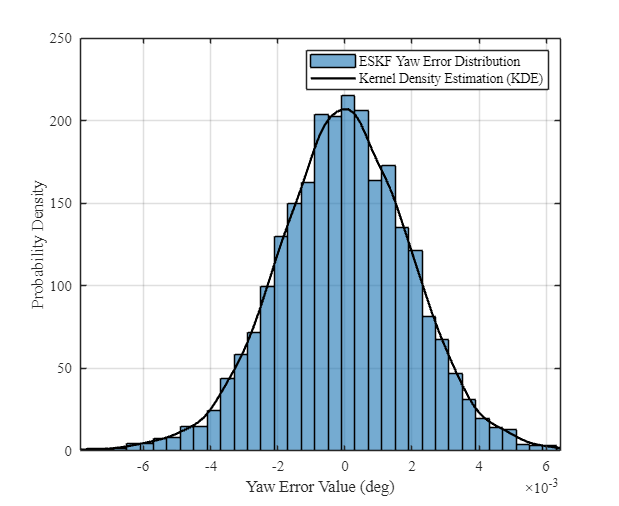

% 7. ESKF error probability distribution histogram (Yaw error)
fig7 = figure('Position', [100, 100, 550, 450], 'Color', 'w');
histogram(error_yaw_eskf, 'Normalization', 'pdf', 'NumBins', 40, 'DisplayName', 'ESKF Yaw Error Distribution', 'FaceColor', color1);
hold on;
[f_eskf, xi_eskf] = ksdensity(error_yaw_eskf);
plot(xi_eskf, f_eskf, 'k-', 'LineWidth', 1.5, 'DisplayName', 'Kernel Density Estimation (KDE)');
hold off;
xlabel('Yaw Error Value (deg)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Probability Density', 'FontSize', plotFontSize, 'FontName', fontName);
% title('Yaw Angle Error Distribution (ESKF)', 'FontSize', plotFontSize+1, 'FontName', fontName);
legend('show', 'Location', 'northeast', 'FontSize', plotFontSize-1, 'FontName', fontName);
grid on;
xlim([min(error_yaw_eskf) max(error_yaw_eskf)*0.85]);
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);

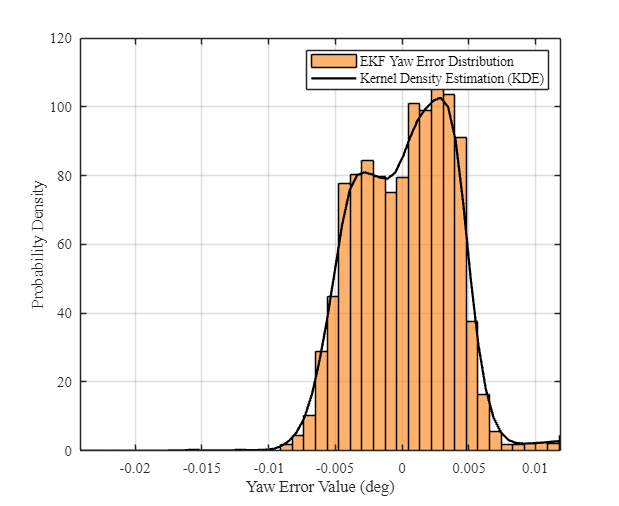

% 8. EKF error probability distribution histogram (Yaw error)
fig8 = figure('Position', [100, 100, 550, 450], 'Color', 'w');
histogram(error_yaw_ekf, 'Normalization', 'pdf', 'NumBins', 60, 'DisplayName', 'EKF Yaw Error Distribution', 'FaceColor', color2);
hold on;
[f_ekf, xi_ekf] = ksdensity(error_yaw_ekf);
plot(xi_ekf, f_ekf, 'k-', 'LineWidth', 1.5, 'DisplayName', 'Kernel Density Estimation (KDE)');
hold off;
xlabel('Yaw Error Value (deg)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Probability Density', 'FontSize', plotFontSize, 'FontName', fontName);
% title('Yaw Angle Error Distribution (EKF)', 'FontSize', plotFontSize+1, 'FontName', fontName);
legend('show', 'Location', 'northeast', 'FontSize', plotFontSize-1, 'FontName', fontName);
grid on;
xlim([min(error_yaw_ekf)*0.7 max(error_yaw_ekf)*0.7]);
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);

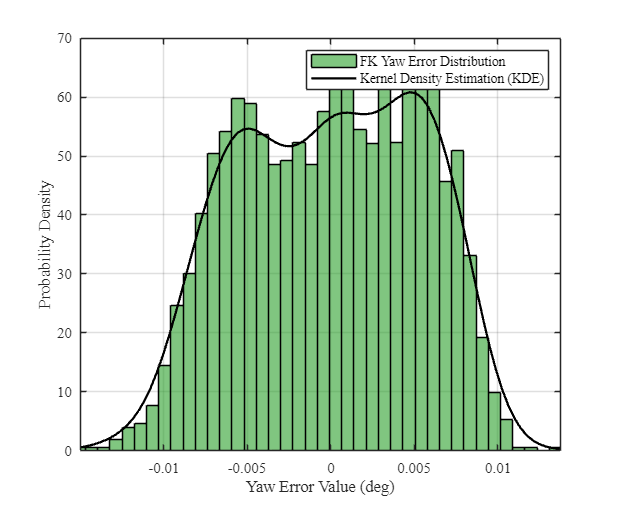

% 9. FK error probability distribution histogram (Yaw error)
fig9 = figure('Position', [100, 100, 550, 450], 'Color', 'w');
histogram(error_yaw_fk, 'Normalization', 'pdf', 'NumBins', 40, 'DisplayName', 'FK Yaw Error Distribution', 'FaceColor', color3);
hold on;
[f_fk, xi_fk] = ksdensity(error_yaw_fk);
plot(xi_fk, f_fk, 'k-', 'LineWidth', 1.5, 'DisplayName', 'Kernel Density Estimation (KDE)');
hold off;
xlabel('Yaw Error Value (deg)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Probability Density', 'FontSize', plotFontSize, 'FontName', fontName);
% title('Yaw Angle Error Distribution (FK)', 'FontSize', plotFontSize+1, 'FontName', fontName);
legend('show', 'Location', 'northeast', 'FontSize', plotFontSize-1, 'FontName', fontName);
grid on;
xlim([min(error_yaw_fk) max(error_yaw_fk)]);
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);

Ts = mean(diff(t_gt));
fs = 1/ Ts;

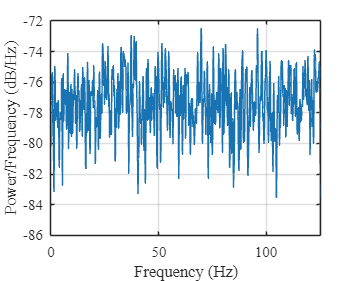

% Define PSD line width
linewidth_psd = 1.0;

% 4. PSD of ESKF error
% fig4 = figure('Position', [100, 100, 550, 450], 'Color', 'w');
fig4 = figure('Position', fig_size, 'Color', 'w');
[pxx, f] = pwelch(error_roll_eskf, [], [], [], fs);
plot(f, 10*log10(pxx), 'LineWidth', linewidth_psd, 'Color', color1);
ylabel('Power/Frequency (dB/Hz)', 'FontSize', plotFontSize, 'FontName', fontName);
xlabel('Frequency (Hz)', 'FontSize', plotFontSize, 'FontName', fontName);
xlim([min(f), max(f)]);
grid on;
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);

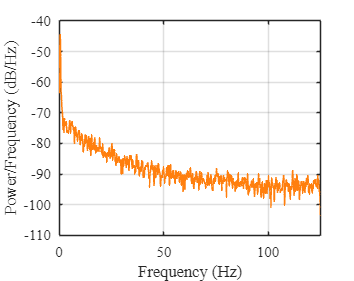

% 5. PSD of EKF error
% fig5 = figure('Position', [100, 100, 550, 450], 'Color', 'w');
fig5 = figure('Position', fig_size, 'Color', 'w');
[pxx, f] = pwelch(error_roll_ekf, [], [], [], fs);
plot(f, 10*log10(pxx), 'LineWidth', linewidth_psd, 'Color', color2);
ylabel('Power/Frequency (dB/Hz)', 'FontSize', plotFontSize, 'FontName', fontName);
xlabel('Frequency (Hz)', 'FontSize', plotFontSize, 'FontName', fontName);
xlim([min(f), max(f)]);
grid on;
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);

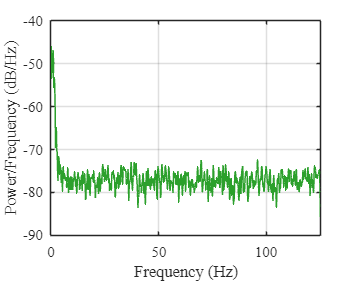

% 6. PSD of FK error
% fig6 = figure('Position', [100, 100, 550, 450], 'Color', 'w');
fig6 = figure('Position', fig_size, 'Color', 'w');
[pxx, f] = pwelch(error_roll_fk, [], [], [], fs);
plot(f, 10*log10(pxx), 'LineWidth', linewidth_psd, 'Color', color3);
ylabel('Power/Frequency (dB/Hz)', 'FontSize', plotFontSize, 'FontName', fontName);
xlabel('Frequency (Hz)', 'FontSize', plotFontSize, 'FontName', fontName);
grid on;
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);
xlim([min(f), max(f)]);


% Define spectrogram parameters
window_length = 128;
overlap_length = round(window_length * 0.75);
nfft = 256;
window = hanning(window_length);

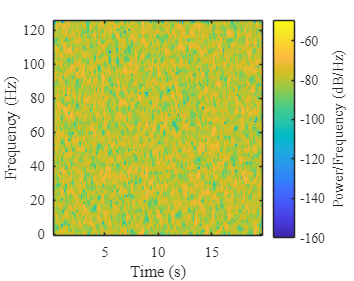

% 7. Spectrogram of ESKF error
% fig7 = figure('Position', [100, 100, 550, 450], 'Color', 'w');
fig7 = figure('Position', fig_size, 'Color', 'w');
spectrogram(error_roll_eskf, window, overlap_length, nfft, fs, 'yaxis');
xlabel('Time (s)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Frequency (Hz)', 'FontSize', plotFontSize, 'FontName', fontName);
h = colorbar;
ylabel(h, 'Power/Frequency (dB/Hz)', 'FontSize', plotFontSize, 'FontName', fontName);
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);
% Unit Color Bar
clim([-160, -50]);

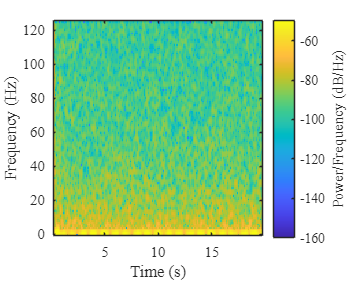

% 8. Spectrogram of EKF error
% fig8 = figure('Position', [100, 100, 550, 450], 'Color', 'w');
fig8 = figure('Position', fig_size, 'Color', 'w');
spectrogram(error_roll_ekf, window, overlap_length, nfft, fs, 'yaxis');
xlabel('Time (s)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Frequency (Hz)', 'FontSize', plotFontSize, 'FontName', fontName);
h = colorbar;
ylabel(h, 'Power/Frequency (dB/Hz)', 'FontSize', plotFontSize, 'FontName', fontName);
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);
clim([-160, -50]);

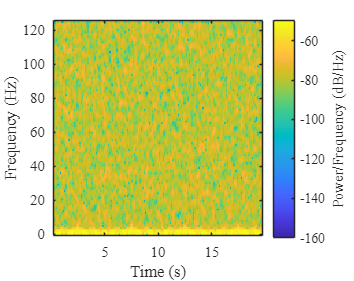

% 9. Spectrogram of FK error
% fig9 = figure('Position', [100, 100, 550, 450], 'Color', 'w');
fig9 = figure('Position', fig_size, 'Color', 'w');
spectrogram(error_roll_fk, window, overlap_length, nfft, fs, 'yaxis');
xlabel('Time (s)', 'FontSize', plotFontSize, 'FontName', fontName);
ylabel('Frequency (Hz)', 'FontSize', plotFontSize, 'FontName', fontName);
h = colorbar;
ylabel(h, 'Power/Frequency (dB/Hz)', 'FontSize', plotFontSize, 'FontName', fontName);
set(gca, 'FontSize', axisFontSize, 'FontName', fontName);
clim([-160, -50]);